ccc

## annex info required

- reference period - Spatial scale (e.g., Global, N America, N Pacific Ocean) - Climate variable (e.g., mean annual temperature) - Data citation (DOI/URL) - Bibliographic reference - Notes (eg download date, website, provided by author, etc) - AR6 section or Figure #

## GMSL estimates - paleo to altim

fname = {
    
    'KE2018'        %01     -500 to 2000    paleo % not going to update for AR6
    
    'CW2011'        %02     1880-2013       EOF   % check if correct update
    'RD2011'        %03     1900-2007       EOF   % discontinued 
    'JE2014'        %04     1900-2009       virtual stations  % potential update pending
    'WS2014'        %05     1902-2007       EOF + neural? % discontinued
    'HA2015'        %06     1880-1990       hybrid CMIP models  (Kalman Smoothing) % discontinued
    
    'DA2017'        %07     1902-2012       virtual stations (modified) 
    'FR2018'        %08     1959-2013       ??                  supersed by FR2020
    'DA2019'        %09     1900-2015       hybrid CMIP models  (Kalman + EOF) % Sonke not going to update for AR6
    'FR2020'        %10     1900-2018       virtual stations (modified) 
    
    'AVISO'         %11     1993-2019       GIA, TPA(?)
    'CMEMS'         %12     1993-2018       GIA(?), TPA
    'CSIRO'         %13     1993-2019       GIA, TPA(?)
    'CU'            %14     1993-2019       No GIA, No TPA
    'ESA'           %15     1993-2019       GIA(?), TPA
    'NASA'          %16     1993-2019       GIA, TPA(?)
    'NOAA'          %17     1993-2019       NO GIA, TPA(?) ** separated by altim missions, need to average together
    'LEGOS'         %18     1993-2016       same as CMEMS but shorter (B.M.)
    
    'PA2021'        %19     1901-2018       Merged Fabio/Matt  % error 1-sigma  =>90%CI: *1.645
    
    };

ffull =  {
        
    ' Kemp et al. 2018'        %01     -500 to 2000    paleo % not going to update for AR6
    
    ' Church & White 2011'        %02     1880-2013       EOF   % check if correct update
    ' Ray & Douglas 2011'        %03     1900-2007       EOF   % discontinued 
    ' Jevrejeva et al. 2014'        %04     1900-2009       virtual stations  % potential update pending
    ' Wenzel & Schroter 2014'        %05     1902-2007       EOF + neural? % discontinued
    ' Hay et al. 2015'        %06     1880-1990       hybrid CMIP models  (Kalman Smoothing) % discontinued
     
    ' Dangendorf et al. 2017'        %07     1902-2012       virtual stations (modified) 
    ' Frederikse et al. 2018'        %08     1959-2013       ??                  supersed by FR2020
    ' Dangendorf et al. 2019'        %09     1900-2015       hybrid CMIP models  (Kalman + EOF) % Sonke not going to update for AR6
    ' Frederikse et al. 2020'        %10     1900-2018       virtual stations (modified) 
    
    ' AVISO'                             %11     1993-2019       GIA, TPA(?)
    ' EU CMEMS'                          %12     1993-2018       GIA(?), TPA
    ' CSIRO'                             %13     1993-2019       GIA, TPA(?)
    ' CU       (Nerem et al. 2018)'                                %14     1993-2019       No GIA, No TPA
    ' ESA     (Legeais et al. 2018)'           %15     1993-2019       GIA(?), TPA
    ' NASA   (Beckley et al. 2017)'          %16     1993-2019       GIA, TPA(?)
    ' NOAA'          %17     1993-2019       NO GIA, TPA(?) ** separated by altim missions, need to average together
    ' LEGOS (Blazquez et al. 2018)'         %18     1993-2016       same as CMEMS but shorter (B.M.)
    
    ' Palmer et al. 2021 (1901-1993)'        %19     1901-2018       Merged Fabio/Matt  % error 1-sigma  =>90%CI: *1.645

};

fdir = '/Users/dom032/Dropbox/Collaboration (2018) - IPCC AR6/Data/03_FGD_duplicate/SL';
fdata = dir(fdir); 

ffile ={

    %'2019_03_25_Kopp_datasets'
    
    'SL_paleo_2018_KE_kemp'

    'SL_recons_2011_CW_AR5_church_white_2011_updated'
    'SL_recons_2011_RD_AR5_ray_2011_discontinued'
    'SL_recons_2014_JE_AR5_sveta_2014'
    'SL_recons_2014_WS_wenzel_discontinued'
    'SL_recons_2015_HA_hay_2015_discontinued'
    'SL_recons_2017_DA_sonke_2017'
    'SL_recons_2018_FR_frederikse_2018'
    'SL_recons_2019_DA_sonke_2019'
    'SL_recons_2020_FR_frederikse_2020'
    
    'SL_altim_AVISO_CNES'
    'SL_altim_CMEMS'
    'SL_altim_CSIRO'
    'SL_altim_CU'
    'SL_altim_ESA_CCI'
    'SL_altim_NASA_GSFC'
    'SL_altim_NOAA_NESDIS_STAR'
    'SL_altim_LEGOS_GRACE'
    'SLEn_Fabio'
    
   };

## allocate GMSL matrices

gmsl_yr_name    =  fname;
gmsl_yr_time    =  -500:1:2020;
gmsl_yr_obs     =  NaN(size(gmsl_yr_name,1),length(gmsl_yr_time));
gmsl_yr_obs_er  =  NaN(size(gmsl_yr_name,1),length(gmsl_yr_time));


%---------------------------------------------------------------------
% EXCEL SPREADSHEET - START
%---------------------------------------------------------------------

## Import data from Bob's spreadsheet

Script for importing data from the following spreadsheet:

To extend the code for use with different selected data or a different spreadsheet, generate a function instead of a script.

% Auto-generated by MATLAB 2017b Update 9 on 2019/03/28 19:14:44

## Import the data

[~, ~, raw] = xlsread([fdir,'/2019_03_25_Kopp_datasets/sealevel.xlsx'],'sealevel');
raw = raw(2:end,:);
raw(cellfun(@(x) ~isempty(x) && isnumeric(x) && isnan(x),raw)) = {''};
stringVectors = string(raw(:,1));
stringVectors(ismissing(stringVectors)) = '';
raw = raw(:,[2,3,4]);

## Replace non-numeric cells with NaN

R = cellfun(@(x) ~isnumeric(x) && ~islogical(x),raw); % Find non-numeric cells
raw(R) = {NaN}; % Replace non-numeric cells

## Create output variable

data = reshape([raw{:}],size(raw));

## Create table

sealevel = table;

## Allocate imported array to column variable names

sealevel.Source = categorical(stringVectors(:,1));
sealevel.t = data(:,1);
sealevel.y = data(:,2);
sealevel.dy = data(:,3);

## Clear temporary variables

clearvars data raw stringVectors R;

## summary

summary(sealevel)

Variables:

    Source: 5526×1 categorical

        Values:

            AVISO                       953.00 
            Church and White 2011       134.00 
            Dangendorf et al., 2017     111.00 
            Dangendorf et al., 2019    1392.00 
            GSFC                        952.00 
            Hay et al., 2015            111.00 
            Jevrejeva et al 2014        110.00 
            Kemp et al., 2018           136.00 
            NOAA                        313.00 
            Nerem et al., 2018          894.00 
            Ray and Douglas 2011        108.00 
            SLcci/ESA                   312.00 

    t: 5526×1 double

        Values:

            Min       -500.00 
            Median    1999.87 
            Max       2019.00 

    y: 5526×1 double

        Values:

            Min        -20.85 
            Median      -1.69 
            Max          5.40 

    dy: 5526×1 double

     


fsource = table2array(sealevel(:,1));
fexcel = unique(fsource);

## variables

sl_time = table2array(sealevel(:,2));
sl = table2array(sealevel(:,3));
sl_er = table2array(sealevel(:,4));

## draft plot

year01=[];
for i = 1:size(fexcel,1)
    figure(i)
    ii = find(fsource == fexcel(i));
    plot(sl_time(ii),sl(ii),'linew',2),hold on
    title([num2str(i),' ' ,string(fexcel(i))],'fontsize',14)
    
    dummy = sl_time(ii); 
    year01(i,1) = dummy(1);
    
    dummy_sl_time{i} = sl_time(ii);
    dummy_sl{i} = sl(ii);
    dummy_sl_er{i} = sl_er(ii);
    dummy_fsource{i} = fsource(ii);
    
end

close all

## excel list

fexcel = 

## sorted

[tsort,isort] = sort(year01);

sort_sl_time  = dummy_sl_time(isort);
sort_sl       = dummy_sl(isort);
sort_sl_er    = dummy_sl_er(isort);
sort_fsource  = dummy_fsource(isort);
sort_fexcel   = fexcel(isort);

## sortedexcel list

sort_fexcel = 

%---------------------------------------------------------------------
% EXCEL SPREADSHEET - END
%---------------------------------------------------------------------

## import order - ORIGINATORS

% fname = {
%     
%     'KE2018'        % 01 excel
%     
%     'CW2011'        % 02
%     'RD2011'        % 03 excel
%     'JE2014'        % 04 excel
%     'WS2014'        % 05
%     'HA2015'        % 06 excel
%     
%     'DA2017'        % 07 excel
%     'FR2018'        % 08
%     'DA2019'        % 09 excel
%     'FR2020'        % 10
%     
%     'AVISO'         % 11
%     'CMEMS'         % 12
%     'CSIRO'         % 13
%     'CU'            % 14
%     'ESA'           % 15
%     'LEGOS'         % 16
%     'NASA'          % 17
%     'NOAA'          % 18
%     
%     };


%---------------------------------------------------------------------
% IMPORT EXCEL SPREADSHEET - START
%---------------------------------------------------------------------

## 'KE2018', paleo, -500 to 2000, 10-yr averages, cm?

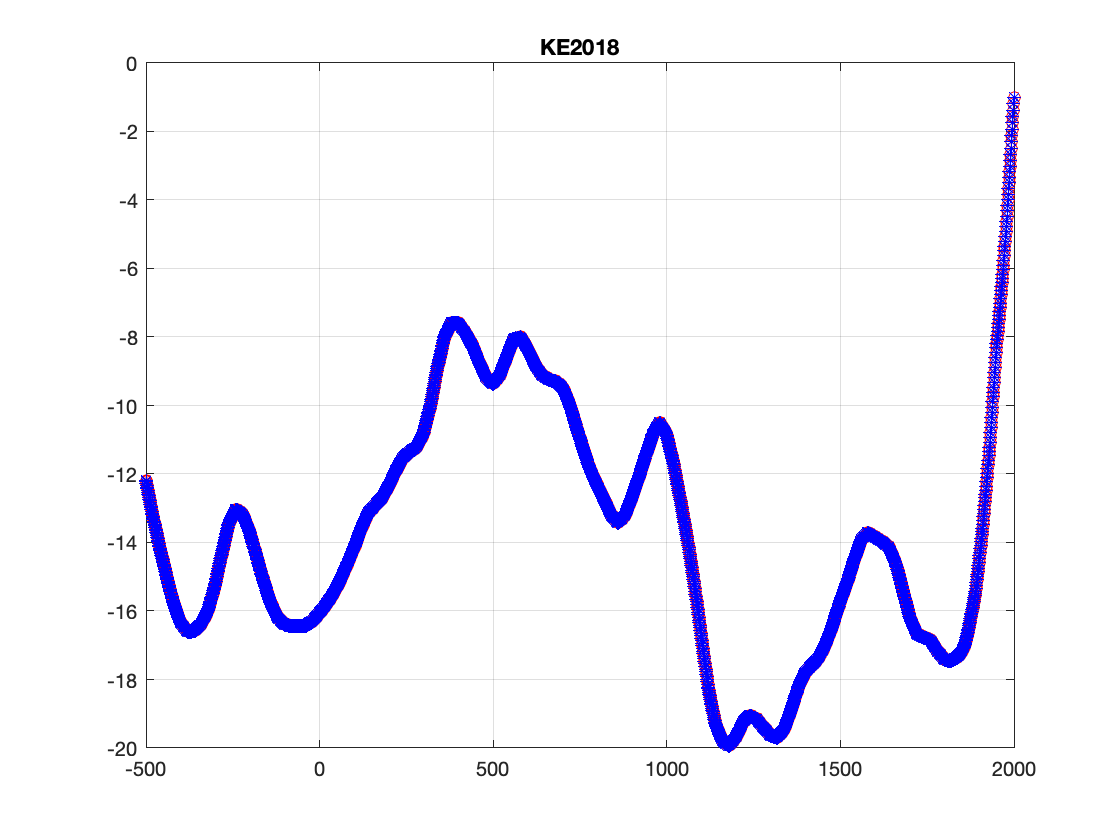

nn  = 1; nobs  = find(startsWith(string(gmsl_yr_name),fname(nn)) == 1);
iobs =[]; iobs  = find(startsWith(string(sort_fexcel),    'Kemp') == 1);

% data source: Bob Kopp, ch9
% reference: https://www.sciencedirect.com/science/article/abs/pii/S0277379118304980?via%3Dihub

    tt=[]; ss =[]; ee =[];
    tt = sort_sl_time{iobs};
    ss = sort_sl{iobs};
    ee = sort_sl_er{iobs};

    % linearly interpolate from 10-yr to annual for plotting purposes
    tt_year=[]; ss_year=[]; ee_year=[];

    tt_year = min(fix(tt)):1:max(fix(tt));
    ss_year = interp1(tt,ss,tt_year,'linear');
    ee_year = interp1(tt,ee,tt_year,'linear');
    % figure,plot(t_year,ss_year,'k-'),hold on,plot(tt,ss,'ro')

    % replace annual averages into ss,ee,tt variables
    tt = tt_year;
    ss = ss_year;
    ee = ee_year;

    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt));
    
    gmsl_yr_obs(nobs,ia)    = ss(ib);
    gmsl_yr_obs_er(nobs,ia) = ee(ib);

    figure(nobs),plot(sort_sl_time{iobs},sort_sl{iobs},'k'),hold on,plot(tt,ss,'ro-'),hold on,plot(gmsl_yr_time,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## 'RD2011' 'JE2014' 'DA2017' yearly, units cm

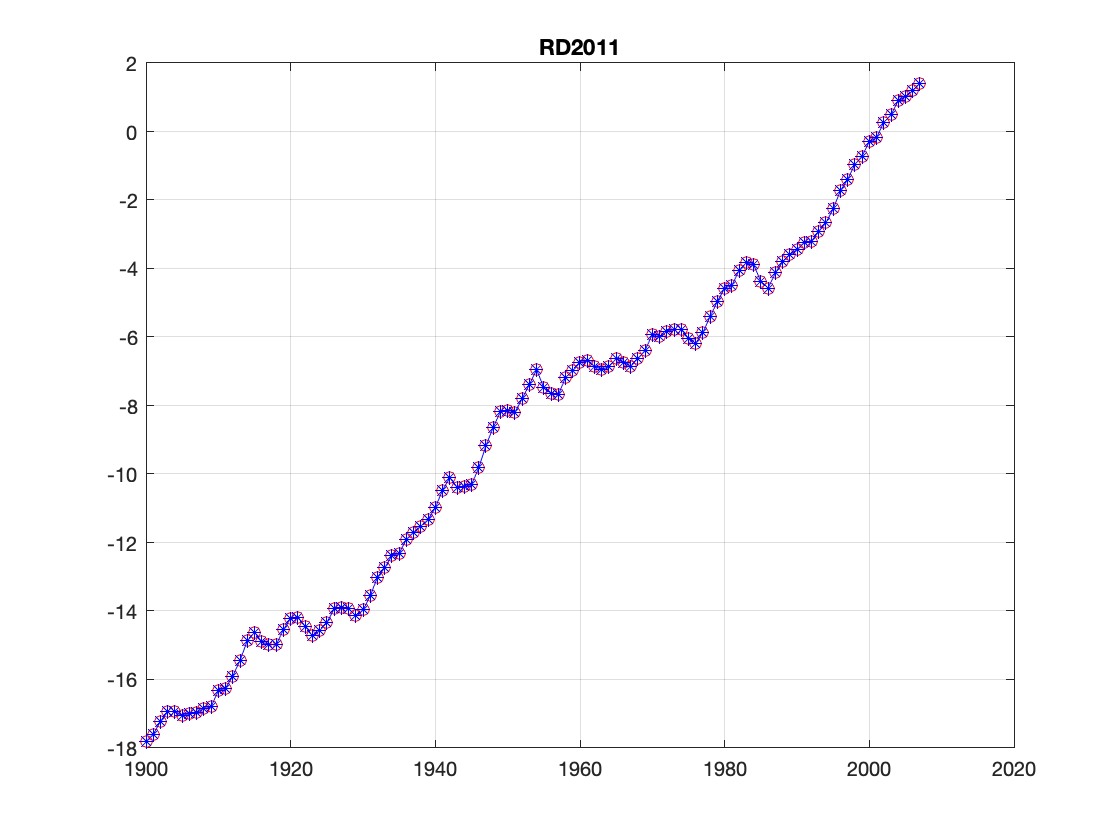

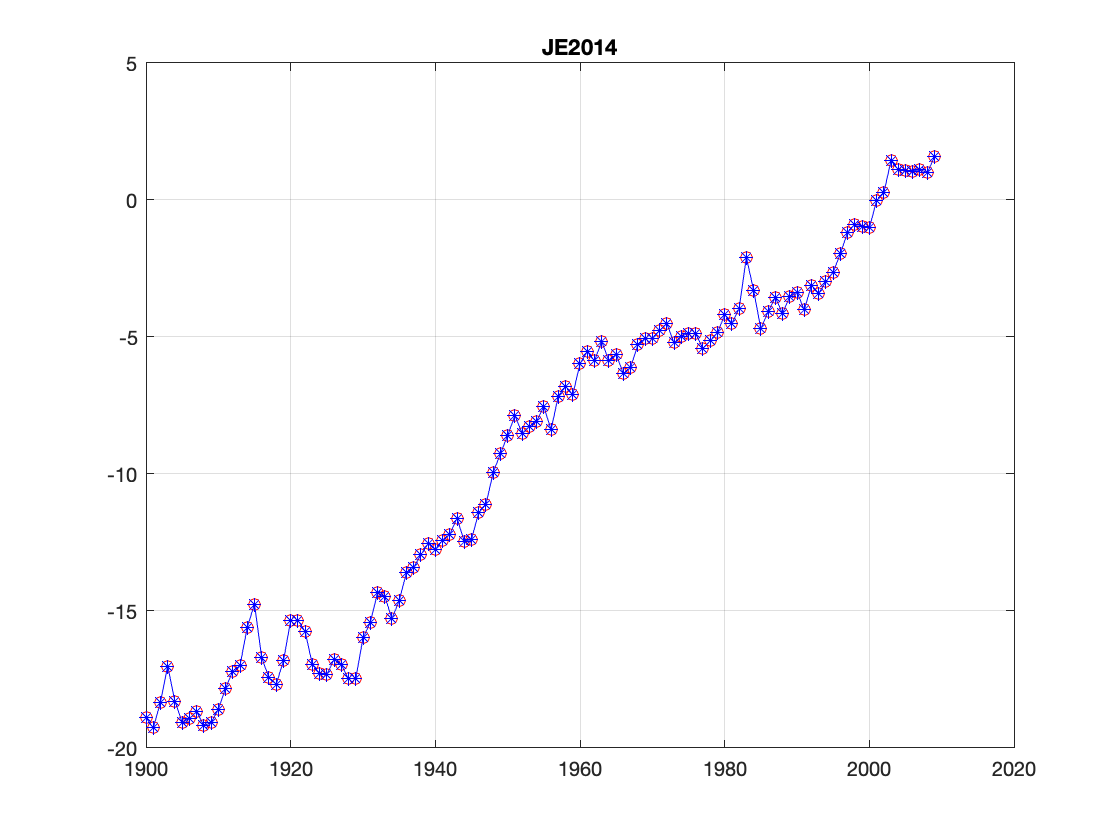

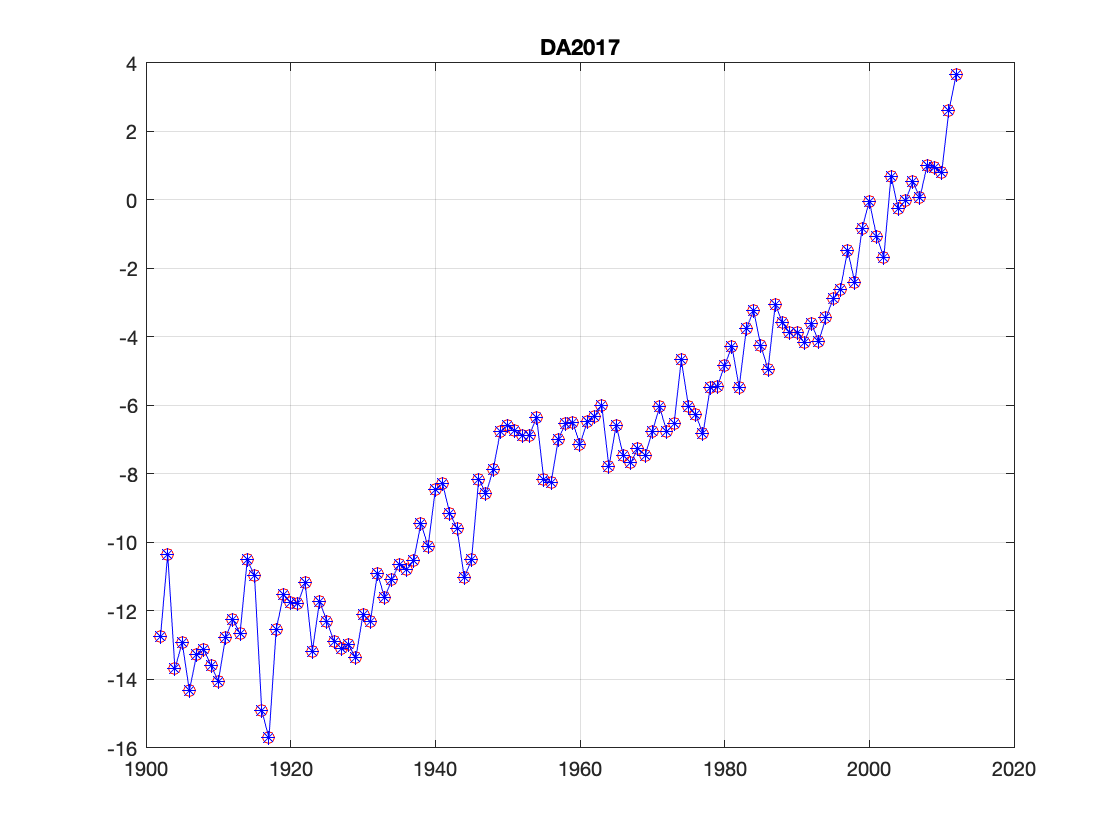

nn  = [ 3 4 7 ];   

iname = {'Ray'; 'Jev'; 'Dangendorf et al., 2017'};

% data source: Bob Kopp, ch9
% references 
% RD2011: https://www.sciencedirect.com/science/article/abs/pii/S0079661111000759
% 1900-2007, yearly, cm

% JE2014: https://www.sciencedirect.com/science/article/abs/pii/S0921818113002750?via%3Dihub  Data source: https://www.psmsl.org/products/reconstructions/gslGPChange2014.txt 
% 1900-2009, yearly, cm

% DA2017: https://www.pnas.org/content/early/2017/05/16/1616007114
% 1902-2012, yearly, cm

    for i = 1:size(iname,1)

        nobs  = find(startsWith(string(gmsl_yr_name),fname(nn(i))) == 1);

        iobs =[];
        iobs = find(startsWith(string(sort_fexcel),iname{i}) == 1);

        tt=[]; ss =[]; ee =[];
        tt = sort_sl_time{iobs};
        ss = sort_sl{iobs};
        ee = sort_sl_er{iobs};

        % insert into big matrix
        ia=[]; ib=[];
        [c,ia,ib] = intersect(gmsl_yr_time,fix(tt));

        gmsl_yr_obs(nobs,ia)    = ss(ib);
        gmsl_yr_obs_er(nobs,ia) = ee(ib);

        figure(nobs),plot(fix(sort_sl_time{iobs}),sort_sl{iobs},'k'),hold on,plot(fix(tt),ss,'ro-'),hold on,plot(gmsl_yr_time,gmsl_yr_obs(nobs,:),'b*-'),grid on
        title(fname{nobs})

    end

## 'DA2019' 1900-2015, hybrid, monthly, cm

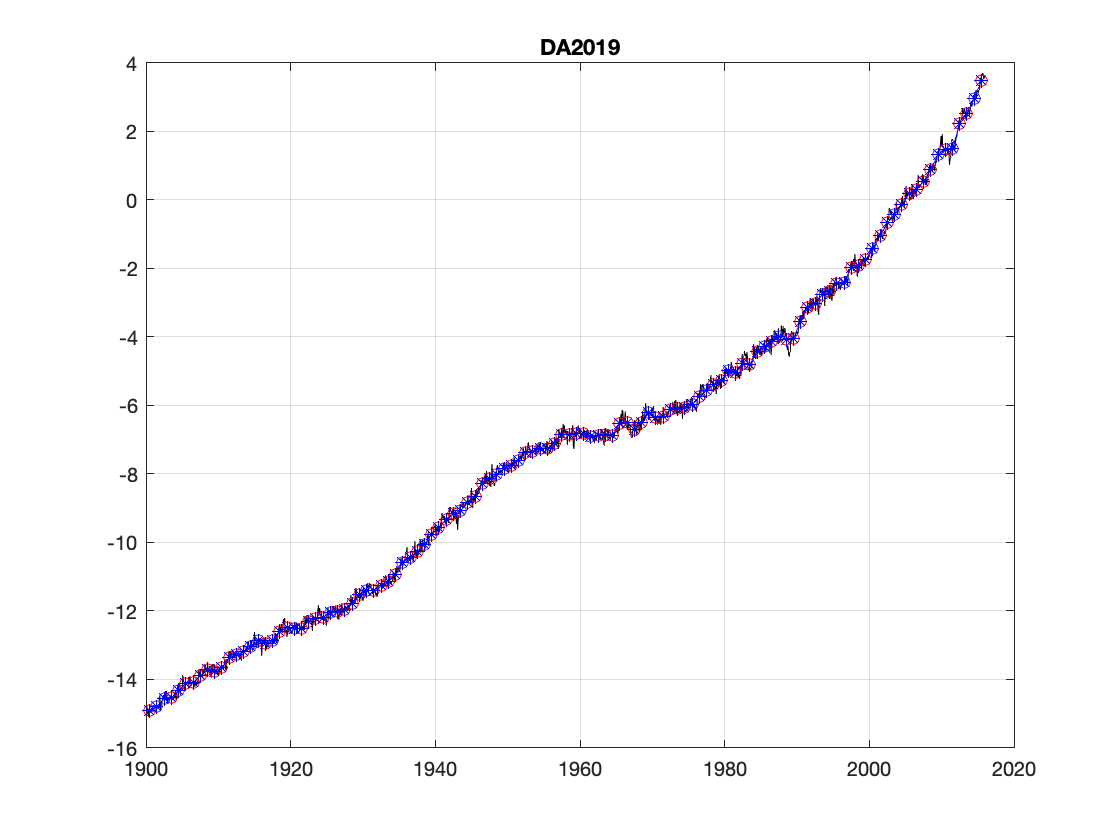

nn   = 9;   

iname = {'Dangendorf et al., 2019'};

% data source: Bob Kopp, ch9
% reference: https://www.nature.com/articles/s41558-019-0531-8

    for i = 1:size(iname,1)

        nobs  = find(startsWith(string(gmsl_yr_name),fname(nn(i))) == 1);

        iobs =[];
        iobs = find(startsWith(string(sort_fexcel),iname{i}) == 1);

        tt=[]; ss =[]; ee =[];
        tt = sort_sl_time{iobs};
        ss = sort_sl{iobs};
        ee = sort_sl_er{iobs};

        % transform into annual averages
        tt_year = fix(min(tt)):1:2018; % end year is 2018
        ss_year =[]; ee_year=[];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

            % there is a problem here, Nerem only has some points in 1992, not the whole year
            % they also only have one point in 2018.. so we need to have at least the whole year for annual averages;
            % to sample timeresolution length
            idum = find(fix(tt) == 2000);
            if length(iyear) >= length(idum)-5
                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear));
            else
                ss_year(year) = NaN;
                ee_year(year) = NaN;
            end

            %disp([ iobs tt_year(year) ss_year(year) sum(ss(iyear))/length(ss(iyear))  ])
        end

        % replace annual averages into ss,ee,tt variables
        tt = tt_year;
        ss = ss_year;
        ee = ee_year;

         % insert into big matrix
        ia=[]; ib=[];
        [c,ia,ib] = intersect(gmsl_yr_time,fix(tt));

        gmsl_yr_obs(nobs,ia)    = ss(ib);
        gmsl_yr_obs_er(nobs,ia) = ee(ib);

        figure(nobs),plot(sort_sl_time{iobs},sort_sl{iobs},'k'),hold on,plot(tt+.5,ss,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
        title(fname{nobs})
    end

## fix units from cm to mm

gmsl_yr_obs     =  10*gmsl_yr_obs;
gmsl_yr_obs_er  =  10*gmsl_yr_obs_er;

%---------------------------------------------------------------------
% IMPORT EXCEL SPREADSHEET - END
%---------------------------------------------------------------------

## 'CW2011' 1880-2013, yearly, with errorbars, units mm

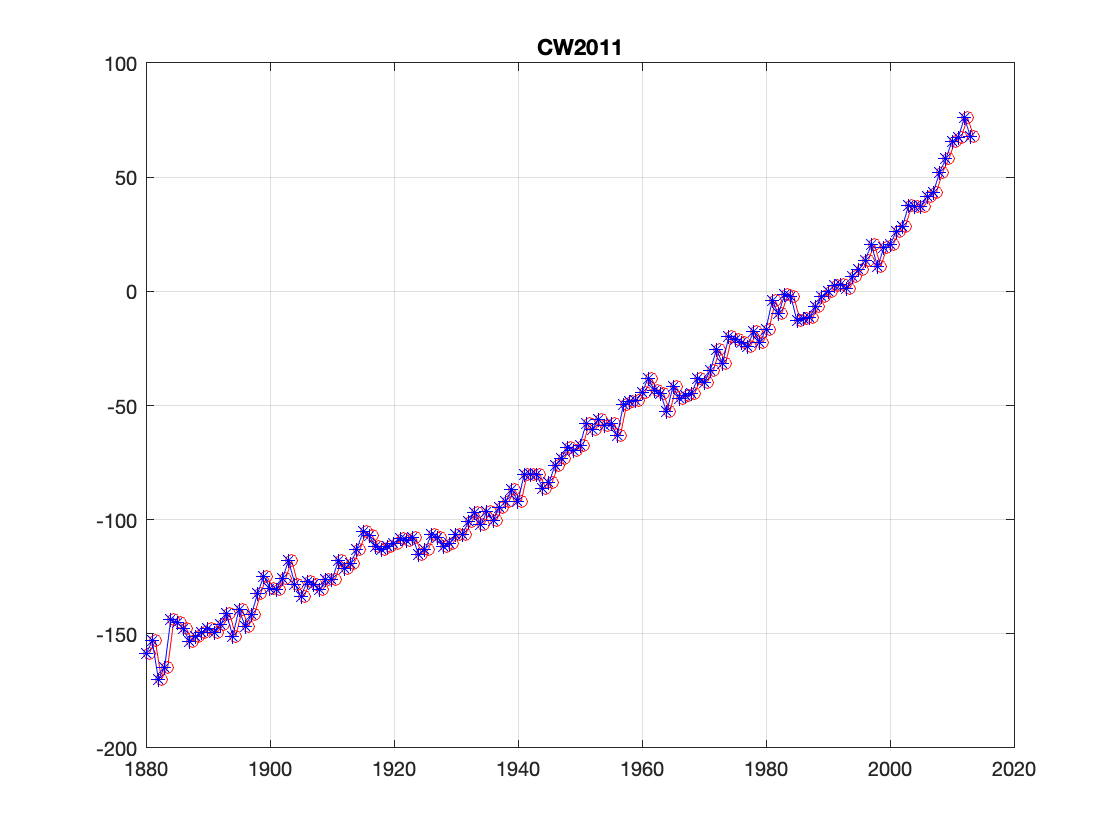

nobs = 2;

% data source: https://www.cmar.csiro.au/sealevel/sl_data_cmar.html
% references:  
% https://link.springer.com/article/10.1007/s10712-011-9119-1
% https://agupubs.onlinelibrary.wiley.com/doi/10.1029/2011GL048794
% Correction: https://agupubs.onlinelibrary.wiley.com/doi/10.1002/grl.50752


dummy =[]; 
dummy = load([fdir,'/',ffile{nobs},'/CSIRO_Recons_gmsl_yr_2015.txt']);

    % replace annual averages into ss,ee,tt variables
    tt = dummy(:,1);
    ss = dummy(:,2);
    ee = dummy(:,3);

    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt));
    
    gmsl_yr_obs(nobs,ia)    = ss(ib);
    gmsl_yr_obs_er(nobs,ia) = ee(ib);

    figure(nobs),plot(tt,ss,'ro-'),hold on,plot(gmsl_yr_time,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## 'WS2014' 1901.5-2008.5, monthly, no errobars, units cm % @ need to double check file => decomposed not total.

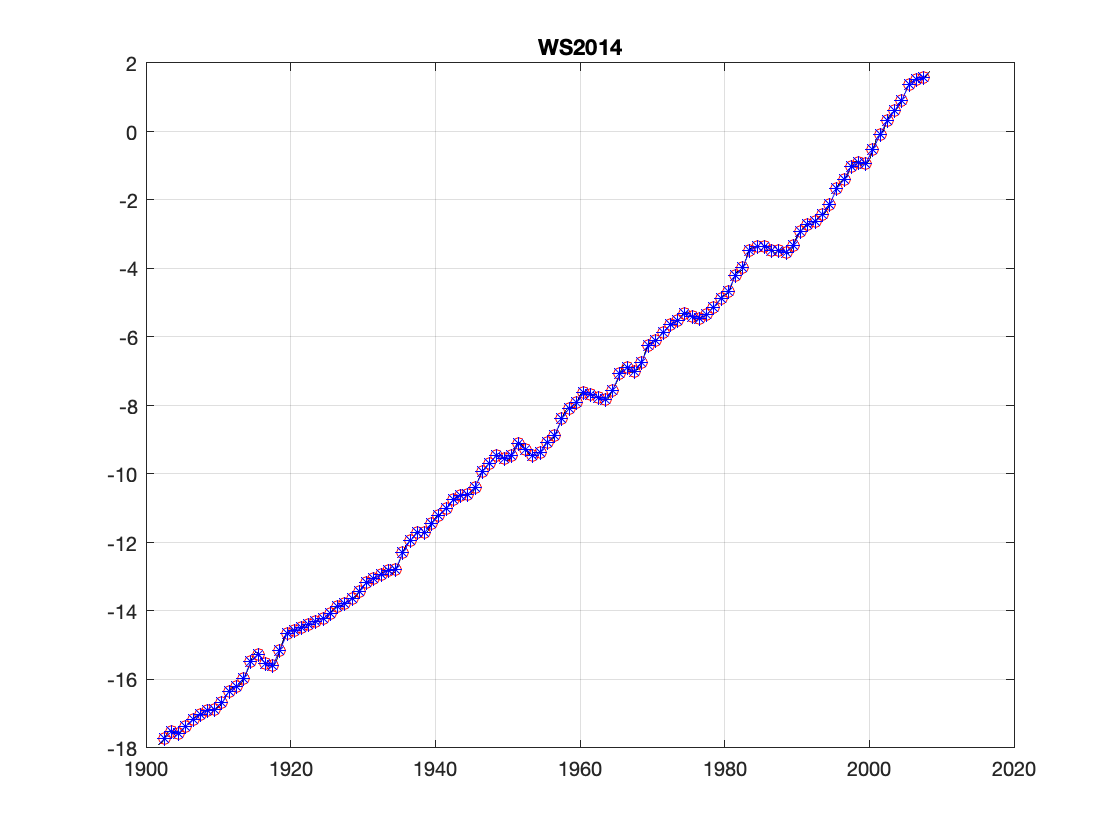

nobs = 5;

% data source: http://store.pangaea.de/Publications/WenzelM_SchroeterJ_2014/WS2014_RSLA_EOF_decomposition.nc
% reference: https://agupubs.onlinelibrary.wiley.com/doi/10.1002/2014JC009900

% This data set contains the EOF decomposition of the reconstructed monthly sea level anomaly (SLA) fields from 1901-09 to 2008-05. 
% The decomposition consists of the global mean sea level anomaly (GMSLA), 12 Empirical Orthogonal Functions (EOF's) estimated 
% from filtered altimetry data (source: CSIRO sea level web page, http://www.cmar.csiro.au/sealevel/sl_data_cmar.html) and 
% the corresponding monthly Principal Components (PC's). The stored GMSLA and PC's are reconstructed using data from 178 tide gauges 
% (see Wenzel and Schröter,2014, for details) considering nine different sets of constraints. 
% The method of reconstruction as well as the constraints are described in Wenzel and Schröter (2014). 
% NOTE: there is no annual cycle in the reconstructed timeseries! The GMSLA is stored as part of the PC and EOF arrays with pcnum=0.
% The monthly sea level anomaly (SLA) fields can finally be composed from the PC's and the EOF's by matrix multiplication:
% SLA(time,lat,lon) = PC(time,pcnum). EOF(pcnum,lat,lon) as outlined in Wenzel and Schröter (2014).


sall = ncread([fdir,'/',ffile{nobs},'/WS2014_RSLA_EOF_decomposition.nc'],'PC_MEAN');
tt =   ncread([fdir,'/',ffile{nobs},'/WS2014_RSLA_EOF_decomposition.nc'],'time');
ss = sall(1,:);
ee = ss*NaN;

        % transform into annual averages for 1902-2007
        tt_year = 1902:1:2007;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear));
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})


% fix units from cm to mm
 
gmsl_yr_obs(nobs,:)     =  10*gmsl_yr_obs(nobs,:);
gmsl_yr_obs_er(nobs,:)  =  10*gmsl_yr_obs_er(nobs,:);

## 'HA2015', yearly, 1900-2010, with error bars, units mm

nobs  = 6;   

iname = {'Hay'};

% HA2015: https://www.sciencedirect.com/science/article/abs/pii/S0277379113005039?via%3Dihub
% HA2015: https://journals.ametsoc.org/jcli/article/30/8/3025/95111/On-the-Robustness-of-Bayesian-Fingerprinting

% Source:

## Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 2020-Sep-24 12:43:38

## Setup the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A4:G114";

% Specify column names and types
opts.VariableNames = ["Year", "GlobalMeanSeaLevelmm", "standarddeviationmm", "VarName4", "Year1", "GlobalMeanSeaLevelmm1", "standarddeviationmm1"];
opts.VariableTypes = ["double", "double", "double", "string", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "VarName4", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "VarName4", "EmptyFieldRule", "auto");

% Import the data
data = readtable([fdir,'/',ffile{nobs},'/41586_2015_BFnature14093_MOESM60_ESM.xls'], opts, "UseExcel", false);
dummy = str2double(table2array(data));

## Clear temporary variables

clear opts

## allocate variables

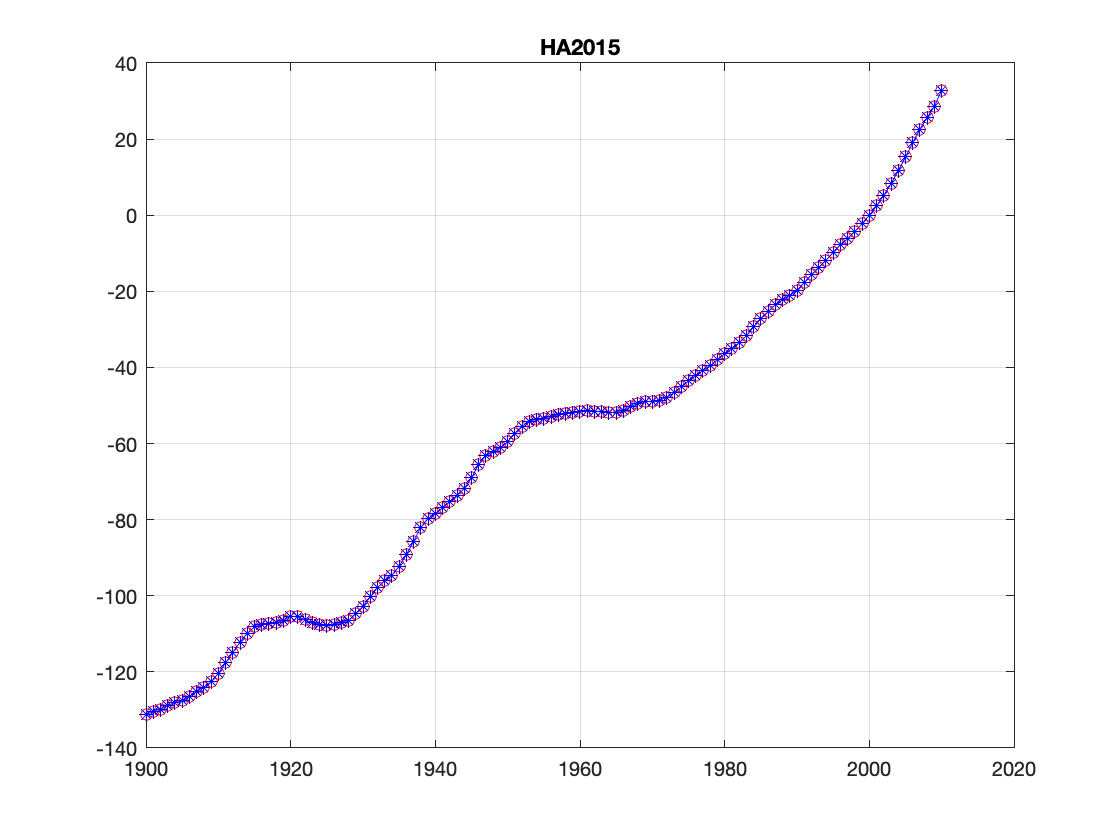

tt =  dummy(:,1);
ss =  dummy(:,2);
ee =  dummy(:,3);

    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt));
    
    gmsl_yr_obs(nobs,ia)    = ss(ib);
    gmsl_yr_obs_er(nobs,ia) = ee(ib);

    figure(nobs),plot(tt,ss,'ro-'),hold on,plot(gmsl_yr_time,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## 'FR2018' 1959-2013, monthly, with errorbars, units mm

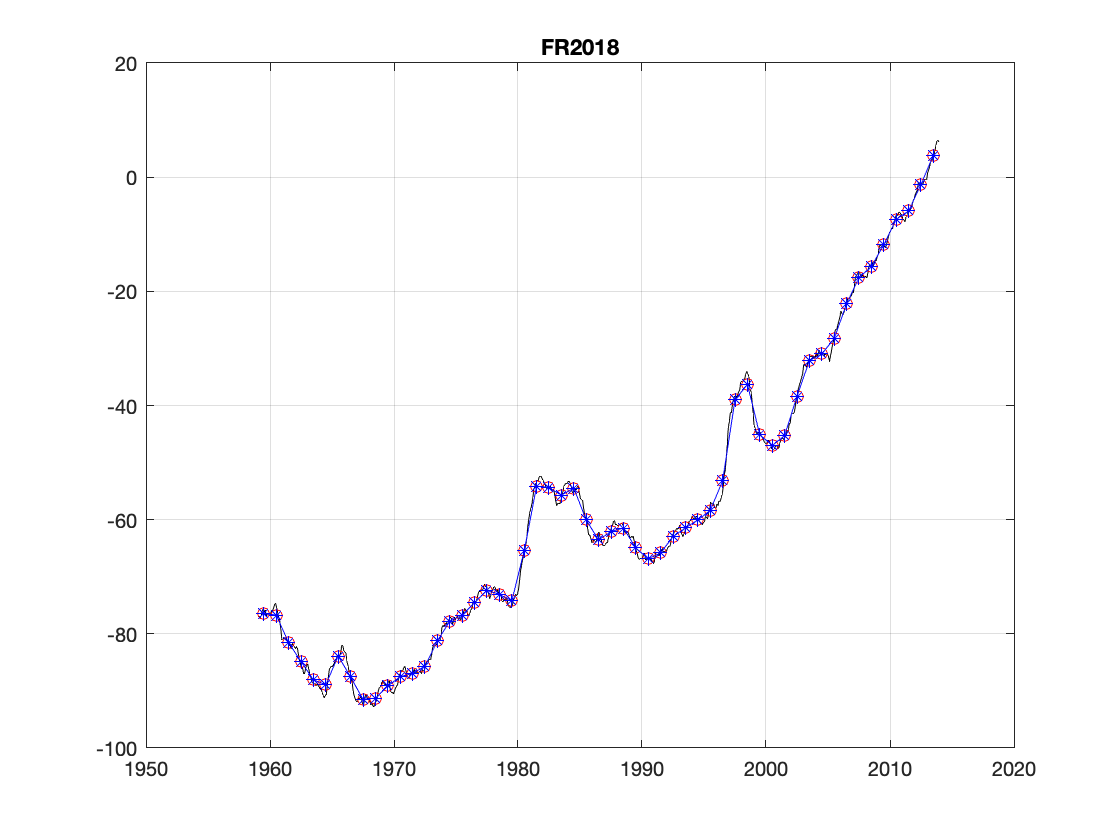

nobs = 8;

% data source: Thomas Frederikse 01/09/2020
% I've attached the reconstruction. ob_m_6.txt is the time series of the mean, and ob_c_6.txt contains the 1-sigma upper- and lower bound. 
% This paper has actually been a bit superseded by the new paper that just came out, but over the overlapping period 1958-2014 
% I think that both reconstructed GMSL time series should be more or less similar. 
% reference: https://journals.ametsoc.org/jcli/article/31/3/1267/107336/A-Consistent-Sea-Level-Reconstruction-and-Its

ob_m_6 = load([fdir,'/',ffile{nobs},'/ob_m_6.txt']);
ob_c_6 = load([fdir,'/',ffile{nobs},'/ob_c_6.txt']);

tt =  ob_m_6(:,1);
ss =  ob_m_6(:,2);
ee =  ob_c_6(1:length(tt),2) - ss; % upper bound



        % transform into annual averages 
        tt_year = 1959:1:2013;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear));
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## 'FR2020' 1900-2018, yearly, with errorbars, units mm

nobs = 10;


% data source: Thomas Frederikse 28/07/2020
% I've attached the proofs and an Excel file with the time series and the uncertainties (5-95 percent). 
% Let me know if you need trends and associated uncertainties over specific periods. 
% On the background, there is an ensemble of sea-level curves with all the uncertainty sources included, 
% from which I can easily compute any quantity with uncertainty estimates.
% reference: https://www.nature.com/articles/s41586-020-2591-3

## Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 2020-Sep-02 18:59:42

## Setup the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 34);

% Specify sheet and range
opts.Sheet = "Global";
opts.DataRange = "A2:AH120";

% Specify column names and types
opts.VariableNames = ["VarName1", "ObservedGMSLlower", "ObservedGMSLmean", "ObservedGMSLupper", "Sumofcontributorslower", "Sumofcontributorsmean", "Sumofcontributorsupper", "Stericlower", "Stericmean", "Stericupper", "Glacierslower", "Glaciersmean", "Glaciersupper", "GreenlandIceSheetlower", "GreenlandIceSheetmean", "GreenlandIceSheetupper", "AntarcticIceSheetlower", "AntarcticIceSheetmean", "AntarcticIceSheetupper", "TerrestrialWaterStoragelower", "TerrestrialWaterStoragemean", "TerrestrialWaterStorageupper", "Reservoirimpoundmentlower", "Reservoirimpoundmentmean", "Reservoirimpoundmentupper", "Groundwaterdepletionlower", "Groundwaterdepletionmean", "Groundwaterdepletionupper", "NaturalTWSlower", "NaturalTWSmean", "NaturalTWSupper", "Altimetrylower", "Altimetrymean", "Altimetryupper"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data & convert table to array
data = readtable([fdir,'/',ffile{nobs},'/global_basin_timeseries.xlsx'], opts, "UseExcel", false);
dummy = table2array(data);

## allocate variables

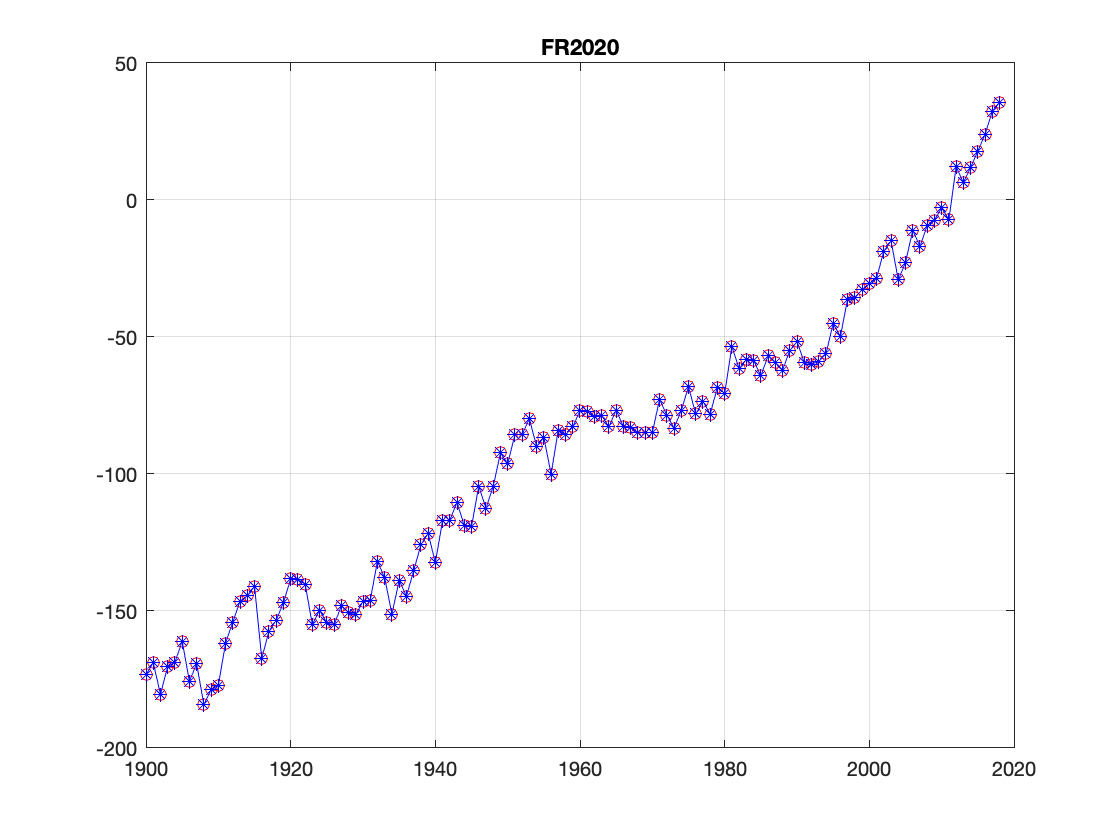

tt =  dummy(:,1);
ss =  dummy(:,3);
ee =  dummy(:,4) - ss; % upper bound

sssum =  dummy(:,6);
eesum =  dummy(:,7) - sssum; % upper bound

    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt));
    
    gmsl_yr_obs(nobs,ia)    = ss(ib);
    gmsl_yr_obs_er(nobs,ia) = ee(ib);

    figure(nobs),plot(tt,ss,'ro-'),hold on,plot(gmsl_yr_time,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})



%%------------------------- ALTIMETER

## 'AVISO' 1993-2020, monthly, no errobars, units m

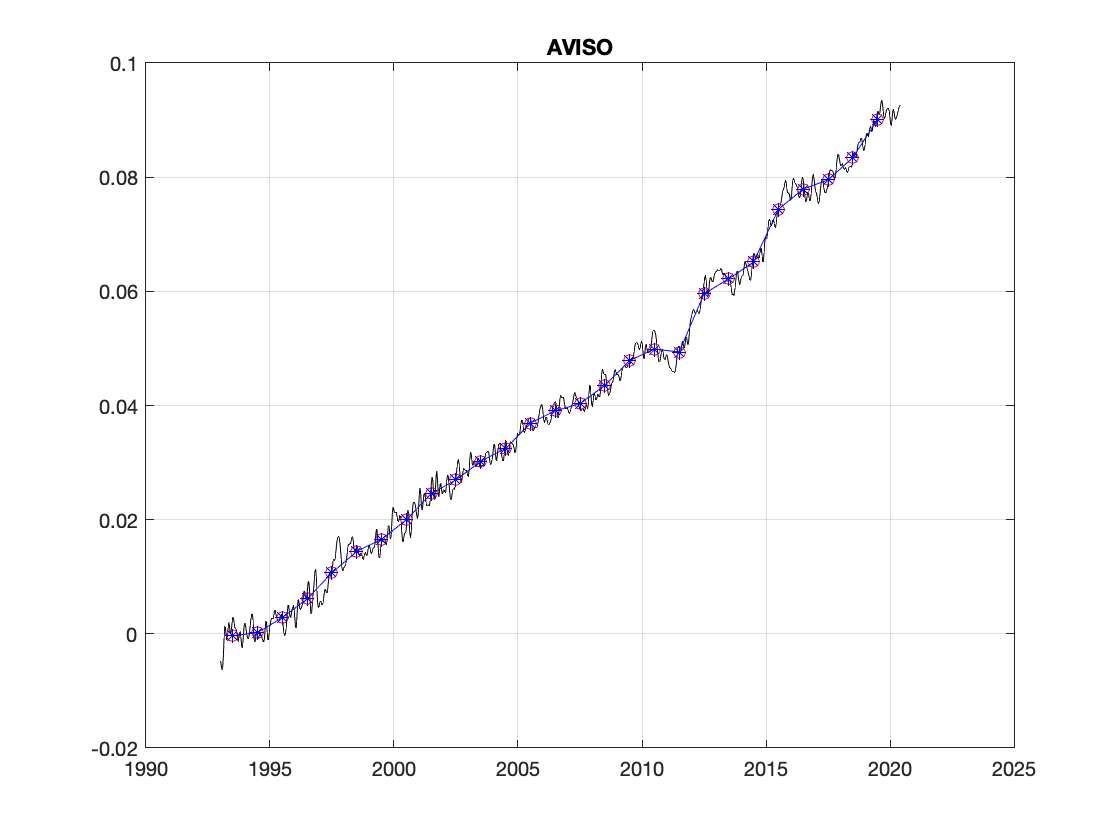

nobs = 11;

% data source: https://www.aviso.altimetry.fr/index.php?id=1599  
% download: 27/07/2020
% reference: 
% netcdf file: Data/03_FGD_duplicate/SL/SL_altim_AVISO_CNES/01_standard/MSL_Serie_MERGED_Global_AVISO_GIA_Adjust_Filter2m.nc 
% {
%   dimensions:
%     time = 1007;
%   variables:
%     double time(time=1007);
%       :units = "days since 1950-01-01";
%       :standard_name = "time";
%       :axis = "T";
% 
%     int cycle(time=1007);
%       :_FillValue = 2147483647; // int
%       :long_name = "cycle number";
% 
%     int pass(time=1007);
%       :long_name = "pass number";
%       :_FillValue = 2147483647; // int
% 
%     double msl(time=1007);
%       :long_name = "mean sea level (satellite=Two-satellites, zone=Global) (sinusoids removed)";
%       :_FillValue = 1.84467440737096E19; // double
%       :standard_name = "sea_surface_height_above_sea_level";
%       :coordinates = "cycle";
%       :units = "m";
% 
%   // global attributes:
%   :references = "http://www.aviso.altimetry.fr";
%   :cls_default_ordinate = "msl";
%   :history = "2020-07-24 22:01:12 : created by aviso@altimetry.fr";
%   :title = "mean sea level";
%   :institution = "CLS";
%   :Conventions = "CF-1.6";
% }

altim = load([fdir,'/',ffile{nobs},'/MSL_Serie_MERGED_Global_AVISO_GIA_Adjust_Filter2m.txt']);

tt =  altim(:,1);
ss =  altim(:,2);
ee =  ss*NaN;



        % transform into annual averages - 1993:2019
        tt_year = 1993:1:2019;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})


% fix units from m to mm
 
gmsl_yr_obs(nobs,:)     =  1000*gmsl_yr_obs(nobs,:);
gmsl_yr_obs_er(nobs,:)  =  1000*gmsl_yr_obs_er(nobs,:);

## 'CMEMS' 1993-2019, daily, no errobars, units m

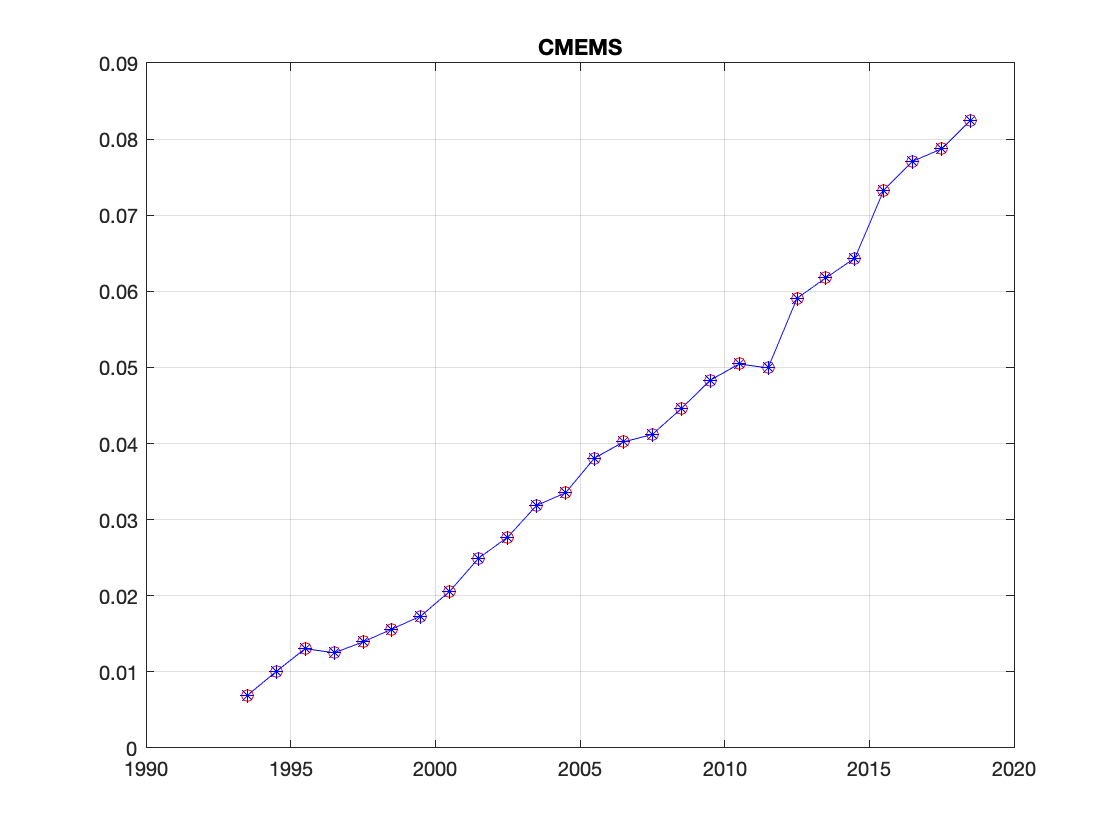

nobs = 12;

% data source: http://www.esa-sealevel-cci.org/products
% email: 31/08/2020 - SL team
% references  - Ablain 2017 + WCRP budget paper
% https://essd.copernicus.org/articles/11/1189/2019/


% netcdf Data/03_FGD_duplicate/SL/SL_altim_CMEMS/global_omi_sl_area_averaged_anomalies_19930101_P20200403.nc 
% {
%   dimensions:
%     time = UNLIMITED;   // (9784 currently)
%   variables:
%     int time(time=9784);
%       :units = "days since 1950-01-01 00:00:00";
%       :standard_name = "time";
%       :calendar = "gregorian";
%       :axis = "T";
%       :_ChunkSizes = 1024U; // uint
% 
%     float sla(time=9784);
%       :units = "m";
%       :long_name = "Sea Level Anomalies";
%       :standard_name = "sea_surface_height_above_sea_level";
%       :_FillValue = 1.0E20f; // float
%       :_ChunkSizes = 979U; // uint
% 
%     float sla_filtered(time=9784);
%       :standard_name = "sea_surface_height_above_sea_level";
%       :units = "m";
%       :long_name = "Filtered Sea Level Anomalies";
%       :_FillValue = 1.0E20f; // float
%       :_ChunkSizes = 979U; // uint
% 
%     float sla_tpacorr(time=9784);
%       :standard_name = "sea_surface_height_above_sea_level";
%       :units = "m";
%       :long_name = "Sea Level Anomalies corrected for the TOPEX-A instrumental drift (Ablain et al., 2017; WCRP Sea Level Budget Group, 2018)";
%       :_FillValue = 1.0E20f; // float
%       :_ChunkSizes = 979U; // uint
% 
%     float sla_filtered_tpacorr(time=9784);
%       :standard_name = "sea_surface_height_above_sea_level";
%       :units = "m";
%       :long_name = "Filtered Sea Level Anomalies corrected for the TOPEX-A instrumental drift (Ablain et al., 2017; WCRP Sea Level Budget Group, 2018)";
%       :_FillValue = 1.0E20f; // float
%       :_ChunkSizes = 979U; // uint
% 
%   // global attributes:
%   :comment = "Period : 1993-01-01 to 2019-10-15.";
%   :title = "Area Averaged Mean Sea Level from DUACS DT2018";
%   :area = "GLOBAL";
%   :Conventions = "CF-1.7";
%   :credit = "E.U. Copernicus Marine Service Information (CMEMS)";
%   :contact = "http://marine.copernicus.eu/services-portfolio/contact-us/";
%   :references = "http://marine.copernicus.eu";
%   :source = "The values are based on the two-satellite merged altimeter sea level product produced by the Copernicus Climate Change Service (C3S) and distributed both by C3S and CMEMS.";
%   :licence = "http://marine.copernicus.eu/services-portfolio/service-commitments-and-licence/";
%   :institution = "CLS";
% }

% need to fix dailies to decimal day
dt = ncread([fdir,'/',ffile{nobs},'/global_omi_sl_area_averaged_anomalies_19930101_P20200403.nc'],'time');
td = datevec(datetime(1950,1,1,'Format','yyyy-MM-dd') + caldays(dt));
tt = td(:,1);
ss =   ncread([fdir,'/',ffile{nobs},'/global_omi_sl_area_averaged_anomalies_19930101_P20200403.nc'],'sla_tpacorr');
ee =  ss*NaN;

ss_filtered_tpacorr =   ncread([fdir,'/',ffile{nobs},'/global_omi_sl_area_averaged_anomalies_19930101_P20200403.nc'],'sla_filtered_tpacorr'); %high freq. var. removed

        % transform into annual averages - 1993:2018
        tt_year = 1993:1:2018;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})


% fix units from m to mm
 
gmsl_yr_obs(nobs,:)     =  1000*gmsl_yr_obs(nobs,:);
gmsl_yr_obs_er(nobs,:)  =  1000*gmsl_yr_obs_er(nobs,:);

## 'CSIRO' 1993-2019, monthly, no errobars, units mm

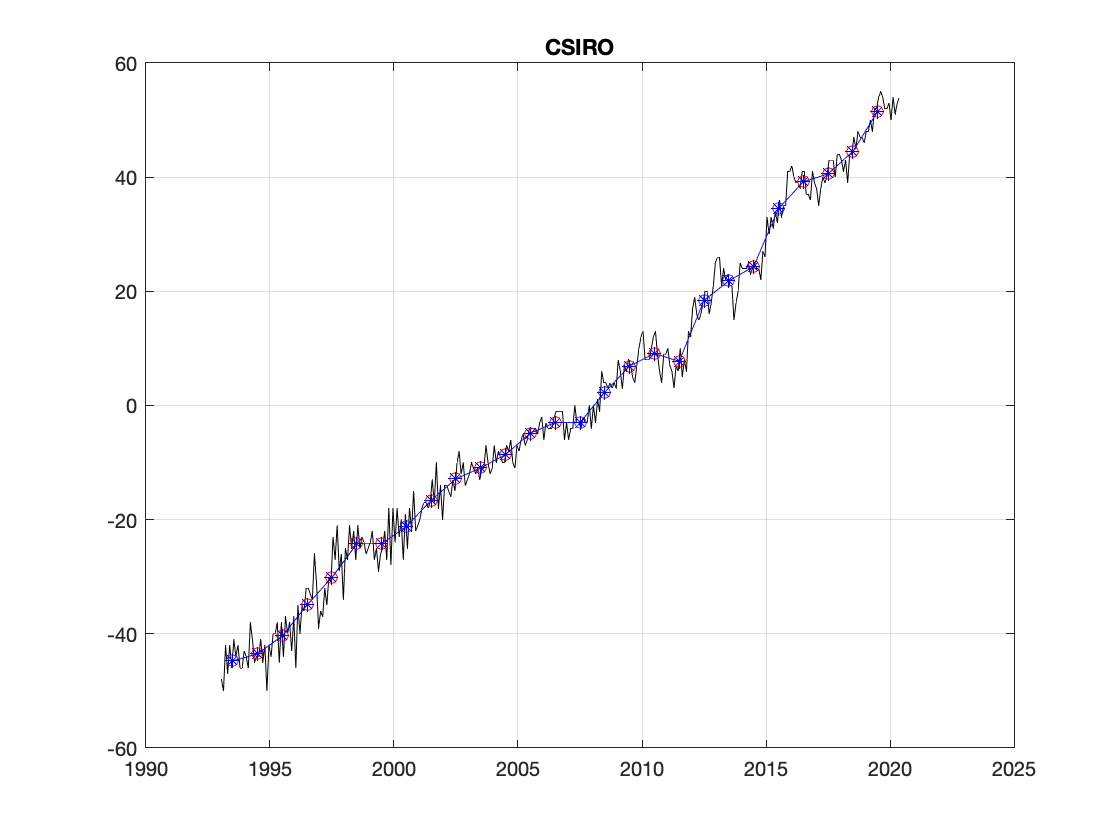

nobs = 13;

% data source: https://www.cmar.csiro.au/sealevel/sl_data_cmar.html
% email: 27/07/2020 - Benoit Legresy
% references  - ?????

% Acknowledgements:
% 
% TOPEX/Poseidon and Jason-1 data were obtained from the NASA Physical Oceanography Distributed Active Archive Center at the Jet Propulsion Laboratory / California Institute of Technology.
% Jason-2/OSTM data was obtained from Aviso (CNES and CLS, France).
% CNES (France) and NASA (USA) for their roles in the TOPEX/Poseidon and Jason-1 missions and for making the data freely available.
% CNES, NASA, NOAA (USA) and EUMETSAT (Europe) for their roles in the Jason-2 and Jason-3 missions and for making the data freely available.
% The many people who have worked to make these missions the successes they have been.


% netcdf Data/03_FGD_duplicate/SL/SL_altim_CSIRO/jb_iby_sry_gtn_giy.nc 
% {
%   dimensions:
%     lon = 360;
%     lat = 131;
%     time = 329;
%   variables:
%     float lon(lon=360);
%       :long_name = "longitude";
%       :units = "degrees_east";
%       :grid = "regular";
%       :minimum = "1.0";
%       :maximum = "360.0";
% 
%     float lat(lat=131);
%       :long_name = "latitude";
%       :units = "degrees_north";
%       :grid = "regular";
%       :minimum = "-65.0";
%       :maximum = "65.0";
% 
%     int time(time=329);
%       :long_name = "central time of month";
%       :units = "days since 1990-01-01 00:00:00";
%       :first_date = "15-JAN-1993";
%       :minimum = "";
%       :maximum = "";
% 
%     int year(time=329);
%       :units = "years";
%       :long_name = "Year";
%       :minimum = "";
%       :maximum = "";
% 
%     int month(time=329);
%       :units = "months";
%       :long_name = "Month";
%       :minimum = "";
%       :maximum = "";
% 
%     float time_years(time=329);
%       :units = "years";
%       :long_name = "Time in f.p. years";
%       :minimum = "";
%       :maximum = "";
% 
%     short alt_map(lat=131, lon=360);
%       :units = "N/A";
%       :long_name = "Altimetry map: 1=good, -1=no data";
%       :minimum = -1.0; // double
%       :maximum = 1.0; // double
% 
%     short height(time=329, lat=131, lon=360);
%       :long_name = "Sea Level Height (mm)";
%       :units = "millimetres";
%       :minimum = "";
%       :maximum = "";
%       :missing_value = 32700.0; // double
%       :FillValue_ = 32700.0; // double
% 
%     short gmsl(time=329);
%       :long_name = "Global mean Sea Level (GMSL) (mm)";
%       :units = "millimetres";
%       :minimum = "";
%       :maximum = "";
% 
%   // global attributes:
%   :description = "T/P + J-1 + J-2 data: Run params: with IB, A+S-A signal removed, Global trend not removed, Altimeter GIA applied";
%   :history = "Created: 17-Jul-2020 17:50:47";
%   :author = "Benoit Legresy";
% }

% dt = ncread([fdir,'/',ffile{nobs},'/jb_iby_sry_gtn_giy.nc'],'time');
% td = datevec(datetime(1990,1,1,'Format','yyyy-MM-dd') + caldays(dt));
% tt = td(:,1);
tt = ncread([fdir,'/',ffile{nobs},'/jb_iby_sry_gtn_giy.nc'],'time_years');
ss = ncread([fdir,'/',ffile{nobs},'/jb_iby_sry_gtn_giy.nc'],'gmsl');
ee = ss*NaN;


        % transform into annual averages - 1993:2019
        tt_year = 1993:1:2019;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## 'CU' 1992-2020, monthly, no errobars, units mm  * NO GIA, NO TPA *

[https://www.pnas.org/content/115/9/2022](https://www.pnas.org/content/115/9/2022)

nobs = 14;

## Import data from text file.

Script for importing data from the following text file:

To extend the code to different selected data or a different text file, generate a function instead of a script.

% Auto-generated by MATLAB on 2020/09/06 18:52:08

## Initialize variables.

filename = [fdir,'/',ffile{nobs},'/cu_gmsl_2020.txt'];

## Format for each line of text:

%	column2: double (%f)
%   column3: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%8f%7f%f%[^\n\r]';

## Open the text file.

fileID = fopen(filename,'r');

## Read columns of data according to the format.

This call is based on the structure of the file used to generate this code. If an error occurs for a different file, try regenerating the code from the Import Tool.

dataArray = textscan(fileID, formatSpec, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string', 'EmptyValue', NaN,  'ReturnOnError', false);

## Close the text file.

fclose(fileID);

## Post processing for unimportable data.

No unimportable data rules were applied during the import, so no post processing code is included. To generate code which works for unimportable data, select unimportable cells in a file and regenerate the script.

## Create output variable

data = table(dataArray{1:end-1}, 'VariableNames', {'VarName1','VarName2','VarName3'});

## Clear temporary variables

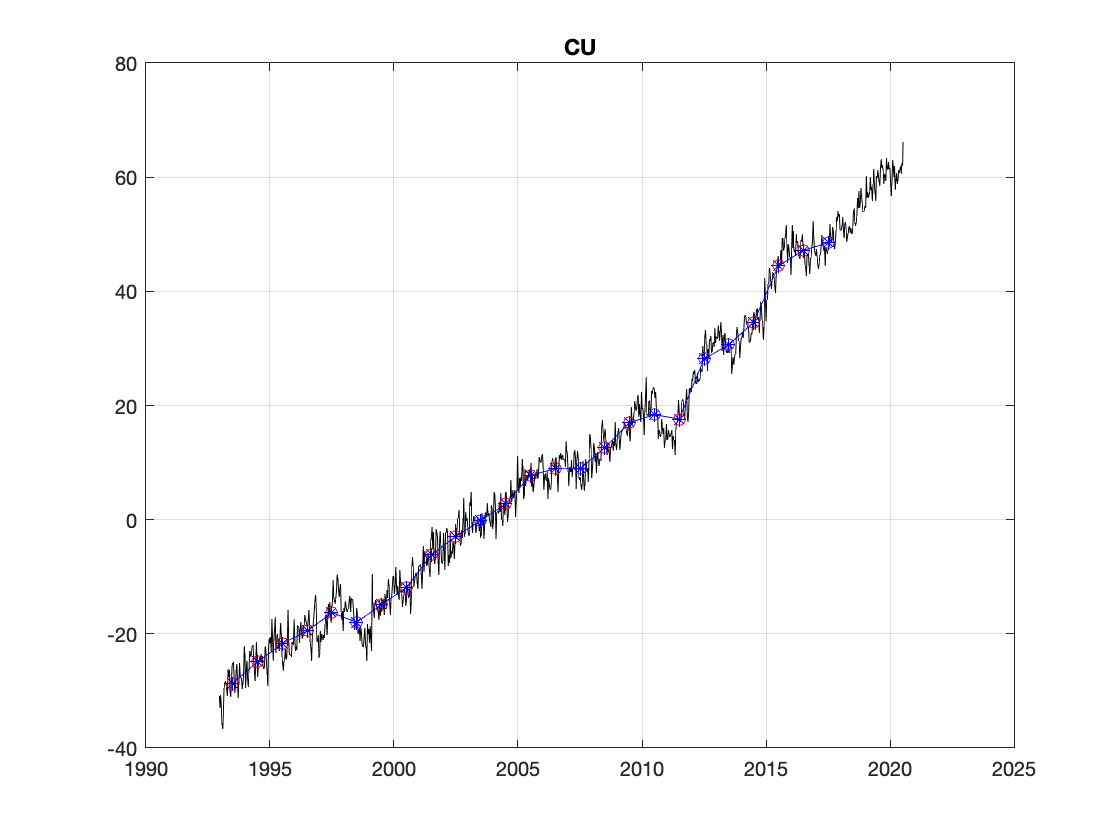

clearvars filename formatSpec fileID dataArray ans;

% Import the data
%data  = readtable([fdir,'/',ffile{nobs},'/cu_gmsl_2020.txt'], opts);

dummy = table2array(data);

tt = dummy(:,1);
ss = dummy(:,3);
ee = dummy(:,2)*NaN; % with seasonal cycle

        % transform into annual averages - 1993:2017
        tt_year = 1993:1:2017;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end

    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})


% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % old
% 
% % data source: http://sealevel.colorado.edu https://www.pnas.org/content/115/9/2022
% % references  - https://www.pnas.org/content/115/9/2022
% 
% %# Date	2018_rel1 GMSL w/ seasonal signals and GIA removed (mm)
% % Release Notes
% % 2018 Release 1 (2018-02-11):
% % Switched to RADS base data (see Processing Notes for details).
% % Not applying the TOPEX cal-1 mode correction (Beckley et al, 2017). https://agupubs.onlinelibrary.wiley.com/doi/full/10.1002/2017JC013090
% % Added Jason-3 GDR cycles 1-70.
% 
% %% Import data from text file
% % Script for importing data from the following text file:
% %
% %    filename: /Users/dom032/Dropbox/Collaboration (2018) - IPCC AR6/Data/03_FGD_duplicate/SL/SL_altim_CU/sl_ns_global.txt
% %
% % Auto-generated by MATLAB on 2020-Sep-02 23:06:48
% 
% %% Setup the Import Options and import the data
% opts = delimitedTextImportOptions("NumVariables", 2);
% 
% % Specify range and delimiter
% opts.DataLines = [2, Inf];
% opts.Delimiter = "\t";
% 
% % Specify column names and types
% opts.VariableNames = ["Date", "rel1GMSLwseasonalsignalsandGIAremovedmm"];
% opts.VariableTypes = ["double", "double"];
% 
% % Specify file level properties
% opts.ExtraColumnsRule = "ignore";
% opts.EmptyLineRule = "read";
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 'ESA' 1993-2020, monthly, no errobars, units mm

Legeais, J.-F., Ablain, M., Zawadzki, L., Zuo, H., Johannessen, J. A., Scharffenberg, M. G., Fenoglio-Marc, L., Fernandes, M. J., Andersen, O. B., Rudenko, S., Cipollini, P., Quartly, G. D., Passaro, M., Cazenave, A., and Benveniste, J.: An improved and homogeneous altimeter sea level record from the ESA Climate Change Initiative, Earth Syst. Sci. Data, 10, 281-301, [https://doi.org/10.5194/essd-10-281-2018](https://doi.org/10.5194/essd-10-281-2018), 2018.

Quartly, G. D., Legeais, J.-F., Ablain, M., Zawadzki, L., Fernandes, M. J., Rudenko, S., Carrère, L., García, P. N., Cipollini, P., Andersen, O. B., Poisson, J.-C., Mbajon Njiche, S., Cazenave, A., and Benveniste, J.: A new phase in the production of quality-controlled sea level data, Earth Syst. Sci. Data, 9, 557-572, [https://doi.org/10.5194/essd-9-557-2017](https://doi.org/10.5194/essd-9-557-2017), 2017.

nobs = 15;

% data source:  Anny Cazenave 30/07/2020
% references  - https://essd.copernicus.org/articles/10/281/2018/

% Source (1) ESA Climate Change Initiative (SL_CCI) - (2) CMEMS - (3) Near Real Time data Jason-3
% Date (decyears) Sea level (mm) Source

## Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 2020-Sep-02 23:40:40

## Setup the Import Options and import the data

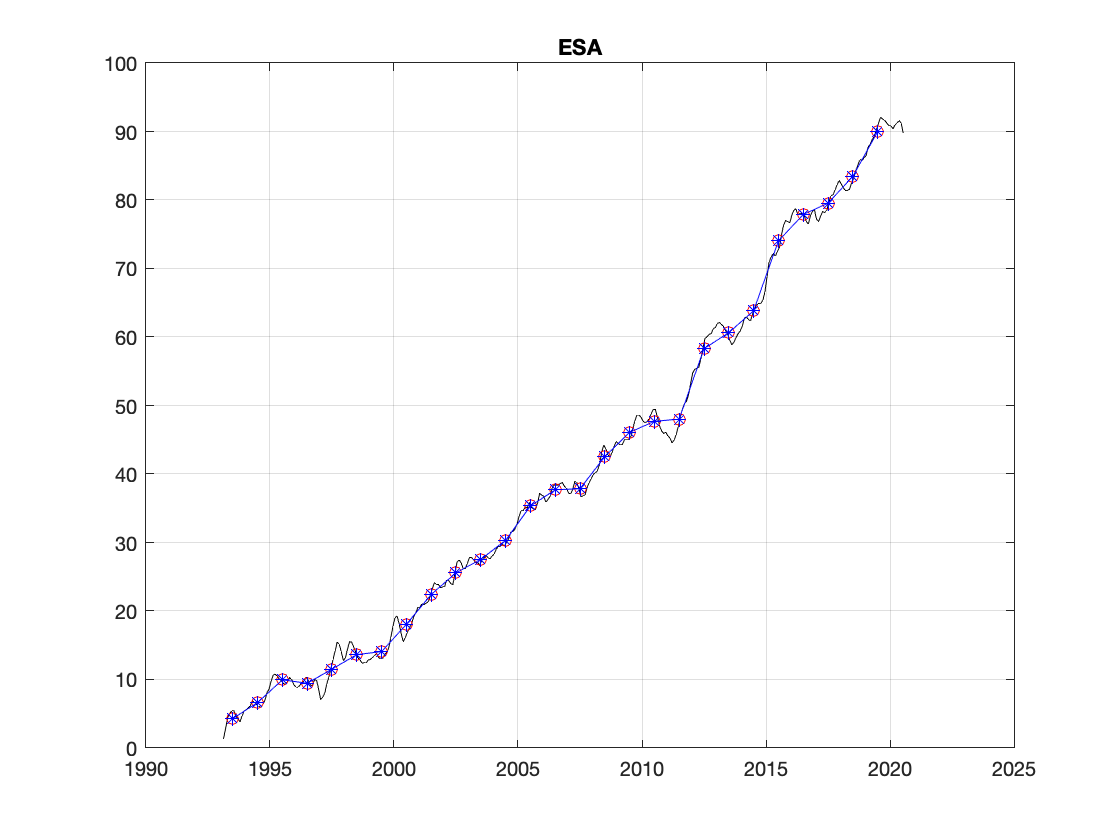

opts = delimitedTextImportOptions("NumVariables", 17, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["Date", "decyears", "Sea", "level", "mm", "Source", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17"];
opts.VariableTypes = ["double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Specify variable properties
opts = setvaropts(opts, ["level", "mm", "Source", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["level", "mm", "Source", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17"], "EmptyFieldRule", "auto");

% Import the data
data = readtable([fdir,'/',ffile{nobs},'/GMSL_CCI_CMEMS_NRTJ3_Ablain_drift_corrected_ts_30Jul2020.txt'], opts);
dummy = table2array(data(:,1:3));

tt = dummy(:,1);
ss = dummy(:,2);
ee = ss*NaN;

        % transform into annual averages - 1993:2019
        tt_year = 1993:1:2019;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## NASA 1993-2020, monthly, no errobars, units mm  * several options

nobs = 16; 

% data source:  https://podaac.jpl.nasa.gov/MEaSUREs-SSH?sections=about%2Bdata
% download: 27/07/2020
% references:   https://agupubs.onlinelibrary.wiley.com/doi/full/10.1002/2017JC013090

%# Date	2018_rel1 GMSL w/ seasonal signals and GIA removed (mm)
% Release Notes
% 2018 Release 1 (2018-02-11):
% Switched to RADS base data (see Processing Notes for details).
% Not applying the TOPEX cal-1 mode correction (Beckley et al, 2017). https://agupubs.onlinelibrary.wiley.com/doi/full/10.1002/2017JC013090
% Added Jason-3 GDR cycles 1-70.

% This folder contains Global Mean Sea Level (GMSL) data and figure produced by Brian Beckley from SGT, Inc. at NASA Goddard Space Flight Center and funded by NASA MEaSUREs.  The GMSL was generated using the Integrated Multi-Mission Ocean Altimeter Data for Climate Research (http://podaac.jpl.nasa.gov/dataset/MERGED_TP_J1_OSTM_OST_ALL_V2).  It combines Sea Surface Heights from TOPEX/Poseidon, Jason-1 and OSTM/Jason-2 with all biases and corrections applied and placed onto a georeferenced orbit.  This creates a consistent data record throughout time, regardless of the instrument used.
% 
% The data can be found in GMSL_TPJAOS_199209_201411.txt.  The figure, GMSL_TPJAOS_199209_201301.tif, was generated using the GMSL data with the 60-day Gaussian type filter and had Global Isostatic Adjustment (GIA) applied.
% 
% If you use these data please cite:
% Beckley, B.; Zelensky, N.P.; Holmes, S.A.;Lemoine, F.G.; Ray, R.D.; Mitchum, G.T.; Desai, S.; Brown, S.T.. 2016. Global Mean Sea Level Trend from Integrated Multi-Mission Ocean Altimeters TOPEX/Poseidon Jason-1 and OSTM/Jason-2 Version 4.2. Ver. 4.2. PO.DAAC, CA, USA. Dataset accessed [YYYY-MM-DD] at http://dx.doi.org/10.5067/GMSLM-TJ142.

% HDR Global Mean Sea Level Data
% HDR
% HDR This file contains Global Mean Sea Level (GMSL) variations computed at the NASA Goddard Space Flight Center under the
% HDR auspices of the NASA MEaSUREs program. The GMSL was generated using the Integrated Multi-Mission Ocean Altimeter Data for
% HDR Climate Research (http://podaac.jpl.nasa.gov/dataset/MERGED_TP_J1_OSTM_OST_ALL_V4.2). It combines Sea Surface Heights from
% HDR TOPEX/Poseidon, Jason-1, OSTM/Jason-2, and Jason-3 to a common terrestrial reference frame with all inter-mission biases, range and
% HDR geophysical corrections applied and placed onto a georeferenced orbit. This creates a consistent data record throughout
% HDR time, regardless of the instrument used.
% HDR
% HDR The data can be found below. A separate figure file, Global_Sea_Level_Graph, was generated using the GMSL data (listed in
% HDR column 12 below) with the 60-day Gaussian type filter and having the Global Isostatic Adjustment (GIA) applied, with annual
% HDR and semi-annual signals removed.
% HDR
% HDR If you use these data please cite:
% HDR GSFC. 2017. Global Mean Sea Level Trend from Integrated Multi-Mission Ocean Altimeters TOPEX/Poseidon, Jason-1, OSTM/Jason-2 Version 4.2 Ver. 4.2 PO.DAAC, CA, USA. Dataset accessed [YYYY-MM-DD] at http://dx.doi.org/10.5067/GMSLM-TJ42.
% HDR
% HDR For information on how the data were generate please refer to:
% HDR* Beckley, B. D., Callahan, P. S., Hancock, D. W., Mitchum, G. T., & Ray, R. D. (2017). On the 'cal-mode'
% HDR correction to TOPEX satellite altimetry and its effect on the global mean sea level time series.
% HDR Journal of Geophysical Research: Oceans, 122. https://doi.org/10.1002/2017JC013090
% HDR
% HDR Beckley, B.D.,  N. P. Zelensky, S. A. Holmes, F. G. Lemoine, R. D. Ray, G. T. Mitchum, S. D. Desai & S. T. Brown, Assessment
% HDR of the Jason-2 Extension to the TOPEX/Poseidon, Jason-1 Sea-Surface Height Time Series for Global Mean Sea Level
% HDR Monitoring, Marine Geodesy, Vol 33, Suppl 1, 2010. DOI:10.1080/01490419.2010.491029
% HDR* As indicated below, heights in various columns are above or below the 20 year time-mean height. If you accessed
% HDR* these data from http://sealevel.nasa.gov or http://climate.nasa.gov, heights plotted there are with respect to the first cycle (January) of 1993.
% HDR
% HDR ====================
% HDR
% HDR Global Mean Sea Level (GMSL) variations from TPJAOS v4.2
% HDR
% HDR column description
% HDR 1 altimeter type 0=dual-frequency  999=single frequency (ie Poseidon-1)
% HDR 2 merged file cycle #
% HDR 3 year+fraction of year (mid-cycle)
% HDR 4 number of observations
% HDR 5 number of weighted observations
% HDR 6 GMSL (Global Isostatic Adjustment (GIA) not applied) variation (mm) with respect to 20-year TOPEX/Jason collinear mean reference
% HDR 7 standard deviation of GMSL (GIA not applied) variation estimate (mm)
% HDR* 8 smoothed (60-day Gaussian type filter) GMSL (GIA not applied) variation (mm)  with respect to 20-year mean
% HDR* 9 GMSL (Global Isostatic Adjustment (GIA) applied) variation (mm) )  with respect to 20-year mean
% HDR 10 standard deviation of GMSL (GIA applied) variation estimate (mm)
% HDR* 11 smoothed (60-day Gaussian type filter) GMSL (GIA applied) variation (mm) )  with respect to 20-year mean
% HDR* 12 smoothed (60-day Gaussian type filter) GMSL (GIA applied) variation (mm); annual and semi-annual signal removed )  with respect to 20-year mean
% HDR
% HDR Missing or bad value flag: 99900.000
% HDR
% HDR* TOPEX/Jason 20 year collinear mean reference is derived from cycles 121 to 858, years 1996-2016.
% HDR

## Import data from text file.

Script for importing data from the following text file:

To extend the code to different selected data or a different text file, generate a function instead of a script.

% Auto-generated by MATLAB on 2020/09/03 00:42:53

## Initialize variables.

filename = [fdir,'/',ffile{nobs},'/GMSL_TPJAOS_4.2_19909_202004_download_2020_07_27_no_header.txt'];

## Format for each line of text:

%	column2: double (%f)
%   column3: double (%f)
%	column4: double (%f)
%   column5: double (%f)
%	column6: double (%f)
%   column7: double (%f)
%	column8: double (%f)
%   column9: double (%f)
%	column10: double (%f)
%   column11: double (%f)
%	column12: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%3f%5f%14f%10f%10f%10f%10f%10f%10f%10f%10f%f%[^\n\r]';

## Open the text file.

fileID = fopen(filename,'r');

## Read columns of data according to the format.

This call is based on the structure of the file used to generate this code. If an error occurs for a different file, try regenerating the code from the Import Tool.

dataArray = textscan(fileID, formatSpec, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string', 'EmptyValue', NaN,  'ReturnOnError', false);

## Close the text file.

fclose(fileID);

## Post processing for unimportable data.

No unimportable data rules were applied during the import, so no post processing code is included. To generate code which works for unimportable data, select unimportable cells in a file and regenerate the script.

## Create output variable

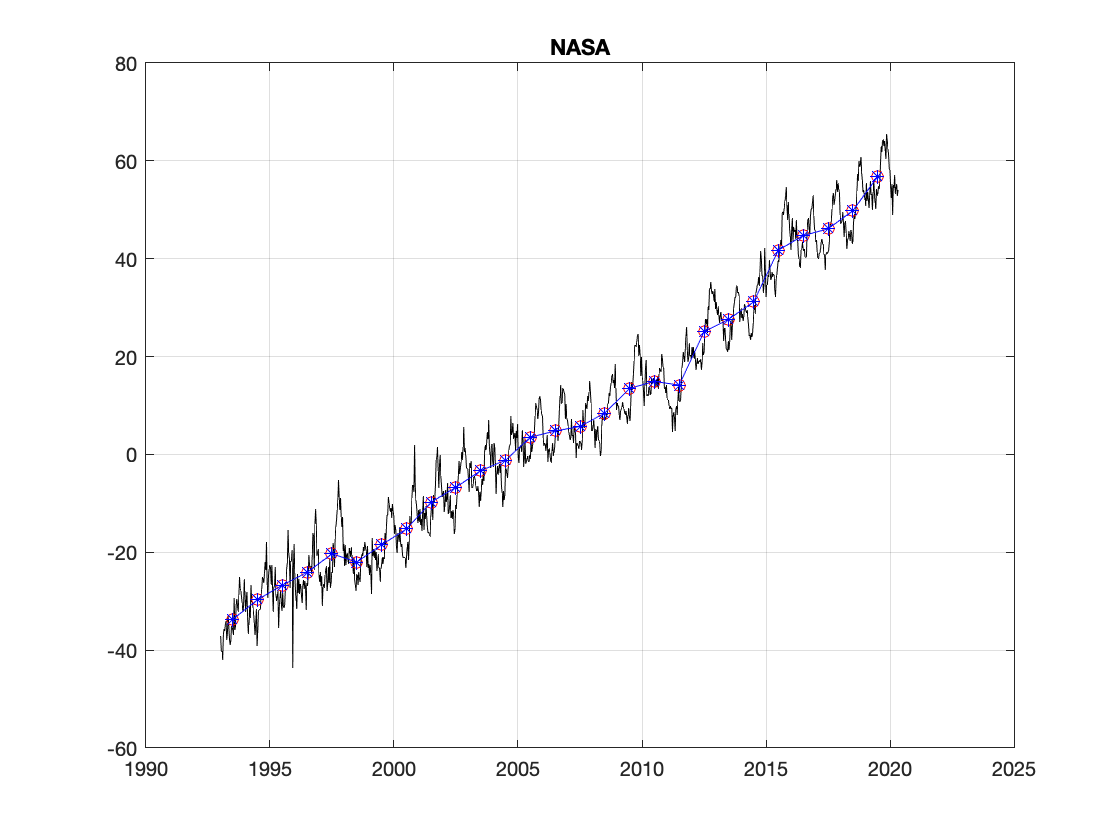

data = table(dataArray{1:end-1}, 'VariableNames', {'VarName1','VarName2','VarName3','VarName4','VarName5','VarName6','VarName7','VarName8','VarName9','VarName10','VarName11','VarName12'});
dummy = table2array(data(:,[3 9 11 12]));
     

tt = dummy(:,1);
ss = dummy(:,2);
ss_smo     = dummy(:,3);
ss_smo_sry = dummy(:,4);
ee = ss*NaN;

        % transform into annual averages - 1993:2019
        tt_year = 1993:1:2019;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## NOAA 1992-2020, monthly, no errobars, units mm  * several options   separated by altim mission

nobs = 17; 


% data source:  https://www.star.nesdis.noaa.gov/socd/lsa/SeaLevelRise/LSA_SLR_timeseries.php
% download: 27/07/2020
% reference:   ??


% File "slr_sla_gbl_free_txj1j2_90.nc"
% File type: NetCDF-3/CDM
%  
% netcdf file:/Users/dom032/Dropbox/Collaboration%20(2018)%20-%20IPCC%20AR6/Data/03_FGD_duplicate/SL/SL_altim_NOAA_NESDIS_STAR/slr_sla_gbl_free_txj1j2_90.nc 
% {
%   dimensions:
%     time_tx = 440;
%     time_j1 = 412;
%     time_j2 = 301;
%     time_j3 = 164;
%   variables:
%     double sla_tx(time_tx=440);
%       :long_name = "TOPEX sea level anomaly";
%       :units = "mm";
% 
%     double time_tx(time_tx=440);
%       :long_name = "TOPEX year";
%       :calendar = "gregorian";
%       :units = "year since 1-1-1 0:0:0";
% 
%     double sla_j1(time_j1=412);
%       :long_name = "Jason-1 sea level anomaly";
%       :units = "mm";
% 
%     double time_j1(time_j1=412);
%       :long_name = "Jason-1 year";
%       :calendar = "gregorian";
%       :units = "year since 1-1-1 0:0:0";
% 
%     double sla_j2(time_j2=301);
%       :long_name = "Jason-2 sea level anomaly";
%       :units = "mm";
% 
%     double time_j2(time_j2=301);
%       :long_name = "Jason-2 year";
%       :calendar = "gregorian";
%       :units = "year since 1-1-1 0:0:0";
% 
%     double sla_j3(time_j3=164);
%       :long_name = "Jason-3 sea level anomaly";
%       :units = "mm";
% 
%     double time_j3(time_j3=164);
%       :long_name = "Jason-3 year";
%       :calendar = "gregorian";
%       :units = "year since 1-1-1 0:0:0";
% 
%   // global attributes:
%   :Conventions = "CF-1.5";
%   :title = "mean sea level anomaly global ocean (Annual signals removed)";
%   :institution = "NOAA/Laboratory for Satellite Altimetry";
%   :source = "satellite radar altimeter from the Radar Altimeter Database System version 4.3.6";
%   :references = "NOAA Sea Level Rise (http://www.star.nesdis.noaa.gov/sod/lsa/SeaLevelRise/) and Radar Altimeter Database System (http://www.deos.tudelft.nl/altim/rads/)";
%   :history = "Generated by \'create_ncfiles plots=txj1j2 var=sla mode=free basin=0 npar=1 lat=90\' at Wed Jul 15 12:15:43 EDT 2020 by leuliett";
%   :comment = "Data use policy: In publications, presentations, or on web pages based on LSA data the following acknowledgment should be included: 
%   \'Altimetry data are provided by NOAA Laboratory for Satellite Altimetry.\'";
%   :trend = "2.96 mm/year (no glacial isostatic adjustment correction)";
% }

## Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 2020-Sep-03 01:32:59

## Setup the Import Options and import the data

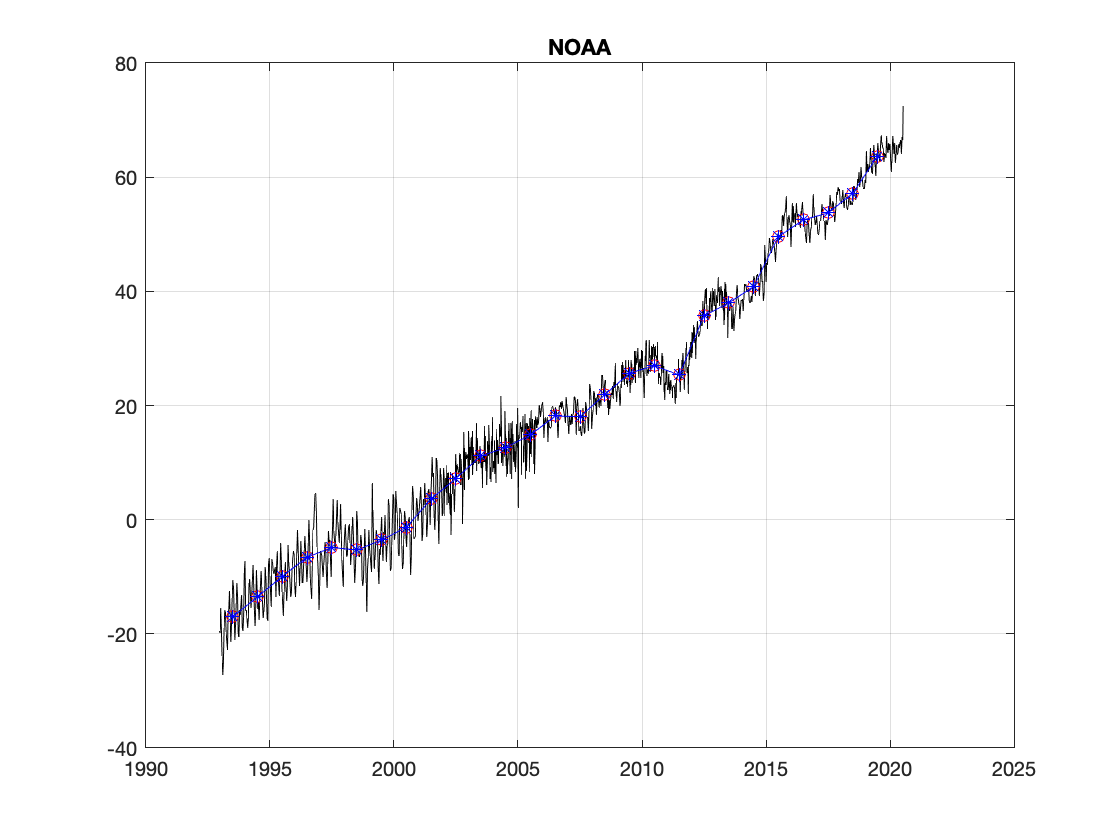

opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [7, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["year", "TOPEXPoseidon", "Jason1", "Jason2", "Jason3"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Jason1", "Jason2", "Jason3"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Jason1", "Jason2", "Jason3"], "ThousandsSeparator", ",");

% Import the data
data = readtable([fdir,'/',ffile{nobs},'/slr_sla_gbl_free_txj1j2_90.csv'], opts);
dummy = table2array(data);
     

tt = dummy(:,1);
ss = nanmean(dummy(:,2:5),2);
ee = ss*NaN;

        % transform into annual averages - 1993:2019
        tt_year = 1993:1:2019;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})

## 'LEGOS' 1993-2017, 10-day, no errobars, units mm

[ftp://ftp.legos.obs-mip.fr/pub/soa/gravimetrie/grace_legos/V1.2/ocean_mass_and_contributors.dat](ftp://ftp.legos.obs-mip.fr/pub/soa/gravimetrie/grace_legos/V1.2/ocean_mass_and_contributors.dat)

updated from 

Blazquez, A., B. Meyssignac, J. M. Lemoine, E. Berthier, A. Ribes, et A. Cazenave. « Exploring the Uncertainty in GRACE Estimates of the Mass Redistributions at the Earth Surface: Implications for the Global Water and Sea Level Budgets ». *Geophysical Journal International* 215, no 1 (1 octobre 2018): 415‑30. [https://doi.org/10.1093/gji/ggy293](https://doi.org/10.1093/gji/ggy293).

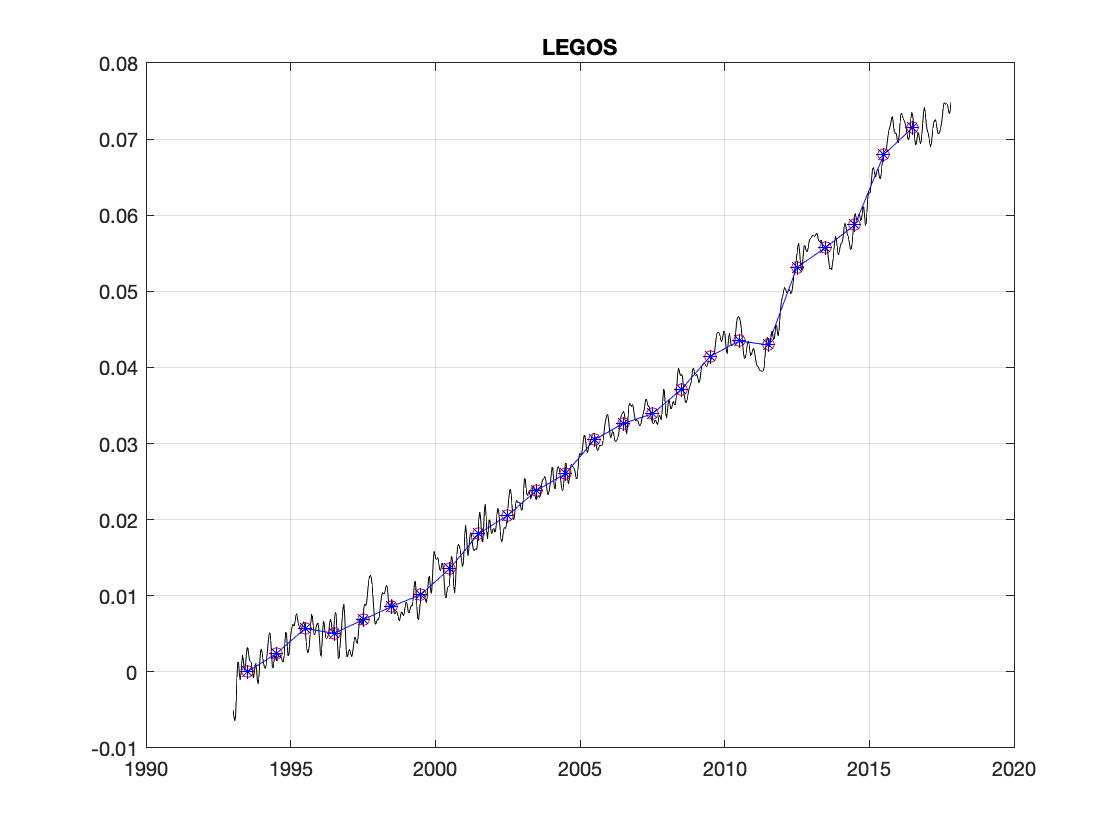

nobs = 18;

% data source:  Benoit Meissignac 08/11/2019
% references  - https://academic.oup.com/gji/article-abstract/215/1/415/5056720?redirectedFrom=fulltext

    
%     netcdf file:/Users/dom032/Dropbox/Collaboration%20(2018)%20-%20IPCC%20AR6/Data/03_FGD_duplicate/SL/SL_altim_LEGOS_GRACE/MSL_Aviso_Correction_GMSL_TPA.nc 
% {
%   dimensions:
%     time = 910;
%   variables:
%     double time(time=910);
%       :units = "days since 1950-01-01";
%       :standard_name = "time";
%       :axis = "T";
% 
%     double tpa_correction(time=910);
%       :long_name = "TOPEX-A GMSL correction derived from altimeter and tg correction";
%       :units = "m";
%       :_FillValue = 1.8446744073709552E19; // double
% 
%     double year(time=910);
%       :standard_name = "year";
%       :axis = "year";
%       :units = "year";
% 
%     double gmsl(time=910);
%       :units = "m";
%       :long_name = "global mean sea level";
%       :_FillValue = 1.8446744073709552E19; // double
% 
%     double gmsl_corrected(time=910);
%       :long_name = "global mean sea level with TOPEX-A GMSL correction applied : gmsl_corrected = gmsl - tpa_correction";
%       :units = "m";
%       :_FillValue = 1.8446744073709552E19; // double
% 
%   // global attributes:
%   :Conventions = "CF-1.6";
%   :title = "GMSL time series from  TP, J1, J2, J3 altimeter missions";
%   :institution = "CLS";
% }


% need to fix dailies to decimal day
tt =  ncread([fdir,'/',ffile{nobs},'/MSL_Aviso_Correction_GMSL_TPA.nc'],'year');
ss =  ncread([fdir,'/',ffile{nobs},'/MSL_Aviso_Correction_GMSL_TPA.nc'],'gmsl_corrected');
ee =  ss*NaN;
 

        % transform into annual averages - 1993:2016
        tt_year = 1993:1:2016;  
        ss_year = []; ee_year = [];

        for year = 1:length(tt_year)
            iyear=[]; 
            iyear = find(fix(tt) == tt_year(year));

                ss_year(year) = mean(ss(iyear));
                ee_year(year) = mean(ee(iyear))*NaN;
        end


    % insert into big matrix
    ia=[]; ib=[];
    [c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));
    
    gmsl_yr_obs(nobs,ia)    = ss_year(ib);
    gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

    figure(nobs),plot(tt,ss,'k-'),hold on,plot(tt_year+.5,ss_year,'ro-'),hold on,plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'b*-'),grid on
    title(fname{nobs})


% fix units from m to mm
 
gmsl_yr_obs(nobs,:)     =  1000*gmsl_yr_obs(nobs,:);
gmsl_yr_obs_er(nobs,:)  =  1000*gmsl_yr_obs_er(nobs,:);

# AR6 assessment

ALTIM

o B eh com o metodo B do matt, ele usou o offset em 1993 entre a TG e altimeters timeseries e somou na serie do altimetro

 merged_SL_TG_altim         120x1               960  double              

 merged_SL_TG_altimB        120x1               960  double              

 merged_error_TG_altim      120x1               960  double              

 merged_time_TG_altim       120x1               960  double              

nobs = 19;

% data source:  Fabio Dias
% references  - Palmer et al. 2021

fbd = load([fdir,'/',ffile{nobs},'/gmsl_altimeter+TG_ensemble_12022021.mat']);

tt_year =  fbd.merged_time_TG_altim;
ss_year =  fbd.merged_SL_TG_altimB;
ee_year =  fbd.merged_error_TG_altim;

% insert into big matrix
ia=[]; ib=[];
[c,ia,ib] = intersect(gmsl_yr_time,fix(tt_year));

gmsl_yr_obs(nobs,ia)    = ss_year(ib);
gmsl_yr_obs_er(nobs,ia) = ee_year(ib);

%% double checking with Matt's file in DMS

%% TG - Import data from text file
% Script for importing data from the following text file:
%
%    filename: /Users/dom032/Dropbox/Collaboration (2018) - IPCC AR6/Data/03_FGD_duplicate/SL/SLEn_Matt/2121_02_24_DMS/AR6 FGD assessment timeseries GMSL tide gauge.csv
%
% Auto-generated by MATLAB on 2021-Feb-24 12:39:21

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Year", "CentralEstimate", "StructuralUnc1sigma", "InternalUnc1sigma", "TotalUnc1sigma"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Matt_TG = readtable("/Users/dom032/Dropbox/Collaboration (2018) - IPCC AR6/Data/03_FGD_duplicate/SL/SLEn_Matt/2121_02_24_DMS/AR6 FGD assessment timeseries GMSL tide gauge.csv", opts);
clear opts

%% ALTIM - Import data from text file
% Script for importing data from the following text file:
%
%    filename: /Users/dom032/Dropbox/Collaboration (2018) - IPCC AR6/Data/03_FGD_duplicate/SL/SLEn_Matt/2121_02_24_DMS/AR6 FGD assessment timeseries GMSL satellite altimeter.csv
%
% Auto-generated by MATLAB on 2021-Feb-24 12:40:59

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Year", "CentralEstimate", "Uncertainty1sigma"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Matt_TP = readtable("/Users/dom032/Dropbox/Collaboration (2018) - IPCC AR6/Data/03_FGD_duplicate/SL/SLEn_Matt/2121_02_24_DMS/AR6 FGD assessment timeseries GMSL satellite altimeter.csv", opts);
clear opts

MTG = table2array(Matt_TG);
MTP = table2array(Matt_TP);




## plot

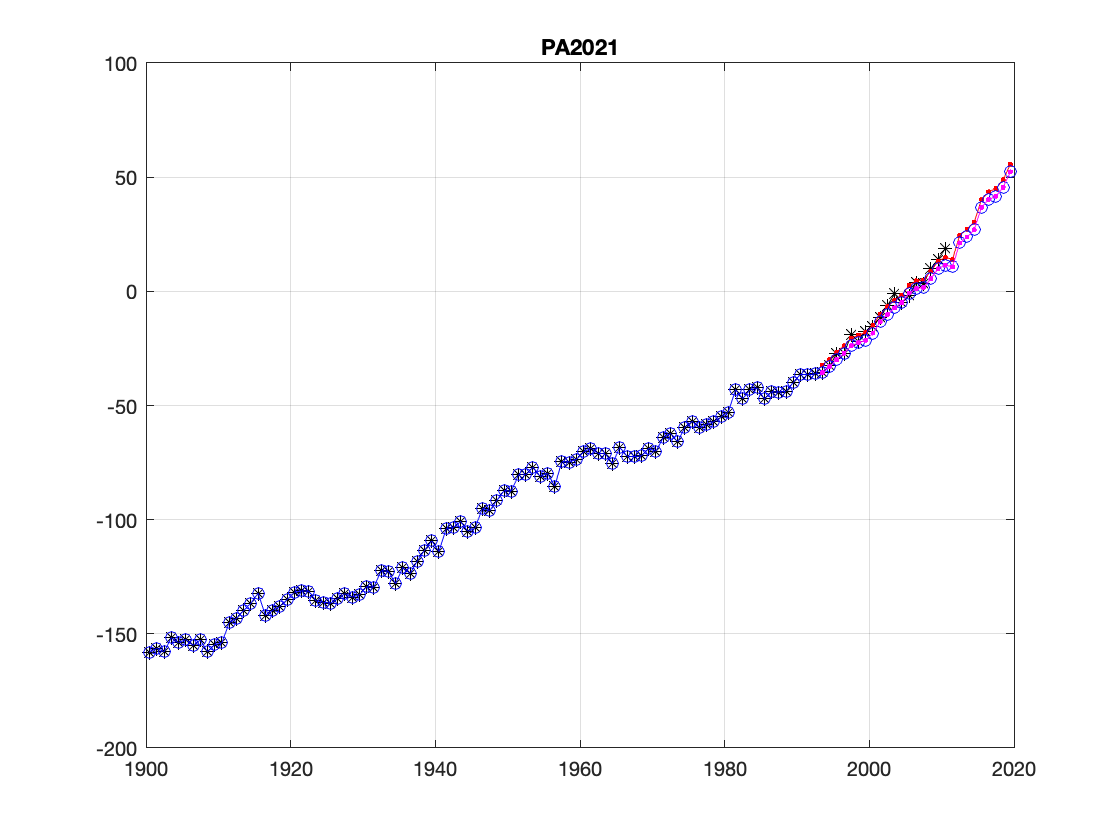



    figure(nobs)
    
    plot(MTG(:,1),MTG(:,2),'k*-'),hold on,plot(MTP(:,1),MTP(:,2),'r.-'),hold on,
    plot(gmsl_yr_time+.5,gmsl_yr_obs(nobs,:),'bo-'),grid on
    ifab = find(gmsl_yr_time >= 1993);
    idff = MTP(1,2) - gmsl_yr_obs(nobs,ifab(1));
    % checking fabio/matt = identical
    plot(MTP(:,1),MTP(:,2)-idff,'m.-')
    title(fname{nobs})

for i = 1:size(fname,1)
    figure(i)
    orient portrait
    ff = ['print /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/fig_GMSL_',fname{i},'.png -dpng'];
    eval(ff)
end

close all

## backup GMSL matrices

gmsl_yr_name_original    =  gmsl_yr_name;
gmsl_yr_time_original    =  gmsl_yr_time; 
gmsl_yr_obs_original     =  gmsl_yr_obs;
gmsl_yr_obs_er_original  =  gmsl_yr_obs_er;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## vertical offsets | figure purposes

## set zeroyear in 1850, adjustment based on Kemp but for all

izero_1850 = gmsl_yr_time == 1850;
  
ikemp  = find(startsWith(string(gmsl_yr_name),'KE2018') == 1);

gmsl_yr_obs = gmsl_yr_obs_original - gmsl_yr_obs_original(ikemp,izero_1850);

## Hay finishes in 1990, fix to match Kemp over 1901-1990

ihay  = find(startsWith(string(gmsl_yr_name),'HA2015') == 1);

imean_1901_1990 = gmsl_yr_time >= 1901 & gmsl_yr_time <= 1990;
 mean_1901_1990_kemp = mean(gmsl_yr_obs(ikemp,imean_1901_1990));
 mean_1901_1990_hay  = mean(gmsl_yr_obs(ihay ,imean_1901_1990));

dummy = gmsl_yr_obs(ihay,:) - mean_1901_1990_hay + mean_1901_1990_kemp;   
gmsl_yr_obs(ihay,:) = dummy;

## baseline period is 1995-2014, however, common period is 1993-2000 (altimeter start year)

imean_1993_2000 =  gmsl_yr_time >= 1993 & gmsl_yr_time <= 2000;
 mean_1993_2000_kemp = mean(gmsl_yr_obs(ikemp,imean_1993_2000));

% baseline 1993-2000
for i = 2:size(gmsl_yr_obs,1)
    mean_1993_2000  = mean(gmsl_yr_obs(i ,imean_1993_2000));
    % excludes Hay which ends in 1990
    if isnan(mean_1993_2000)~=1
        dummy = gmsl_yr_obs(i,:) - mean_1993_2000 + mean_1993_2000_kemp;   
    gmsl_yr_obs(i,:) = dummy;  
    end
end  


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## quick figures

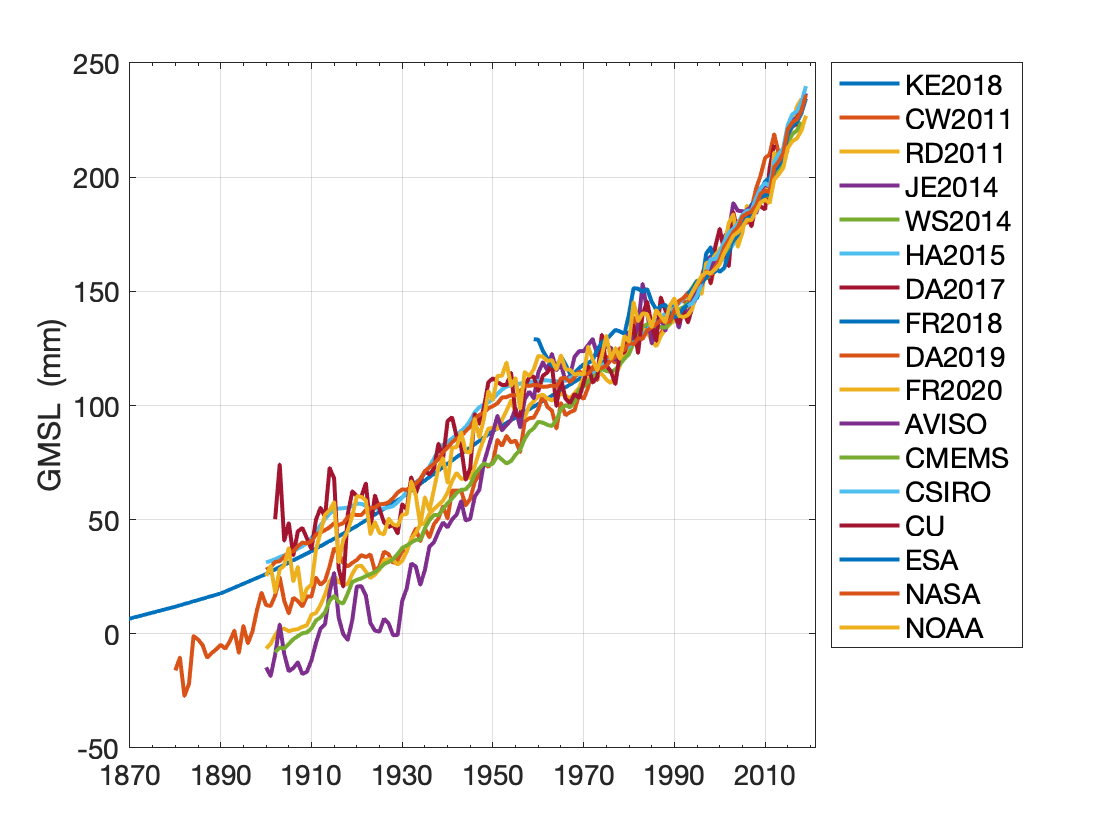

% recons
figure
nn = 1:17;
plot(gmsl_yr_time,gmsl_yr_obs(nn,:),'linew',2),hold on
hleg = legend(fname(nn),'location','bestoutside','fontsize',14);
grid on, axis square
ylabel('GMSL  (mm)')
set(gca,'xtick',1870:20:2022,'xminortick','on','fontsize',14,'xlim',[1870 2021])
orient tall
ff = ['print /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/fig_GMSL_01_ALL_1870_2021.png -dpng'];
eval(ff)

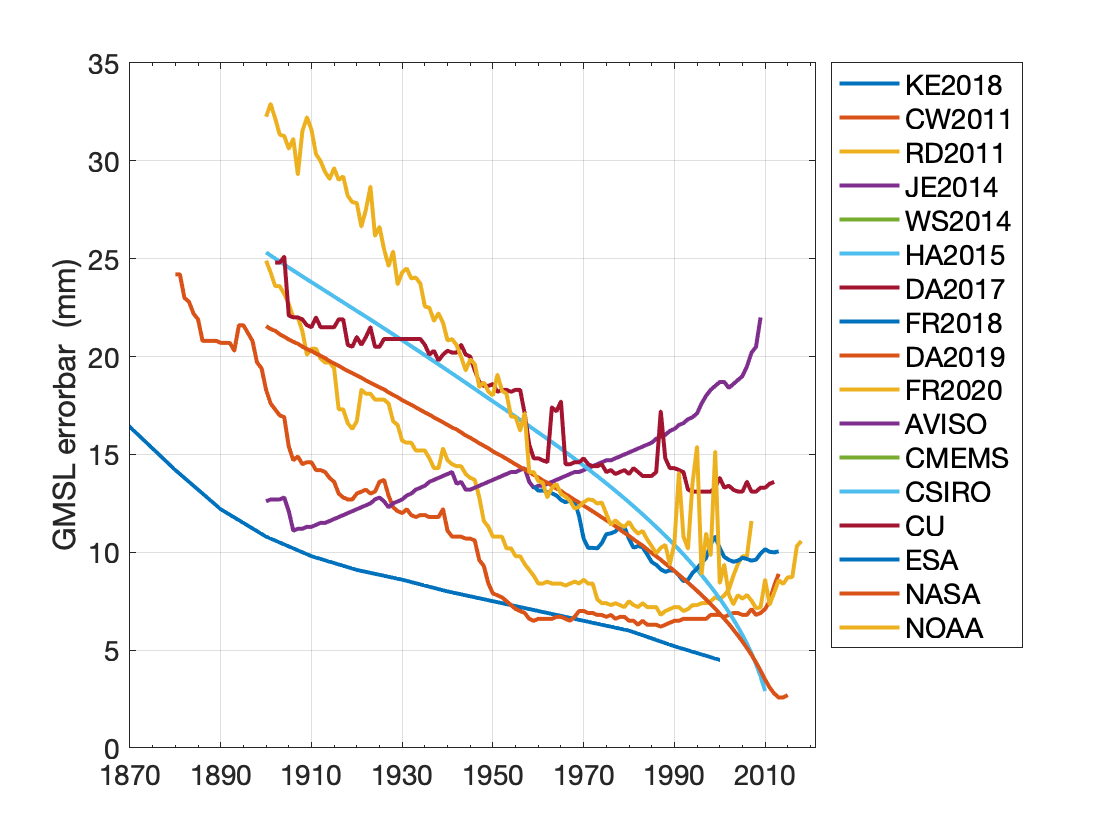


% recons error
figure
nn = 1:17;
plot(gmsl_yr_time,gmsl_yr_obs_er(nn,:),'linew',2),hold on
hleg = legend(fname(nn),'location','bestoutside','fontsize',14);
grid on, axis square
ylabel('GMSL errorbar  (mm)')
set(gca,'xtick',1870:20:2022,'xminortick','on','fontsize',14,'xlim',[1870 2021])
orient tall
ff = ['print /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/fig_GMSL_01_ALL_1870_2021_er.png -dpng'];
eval(ff)

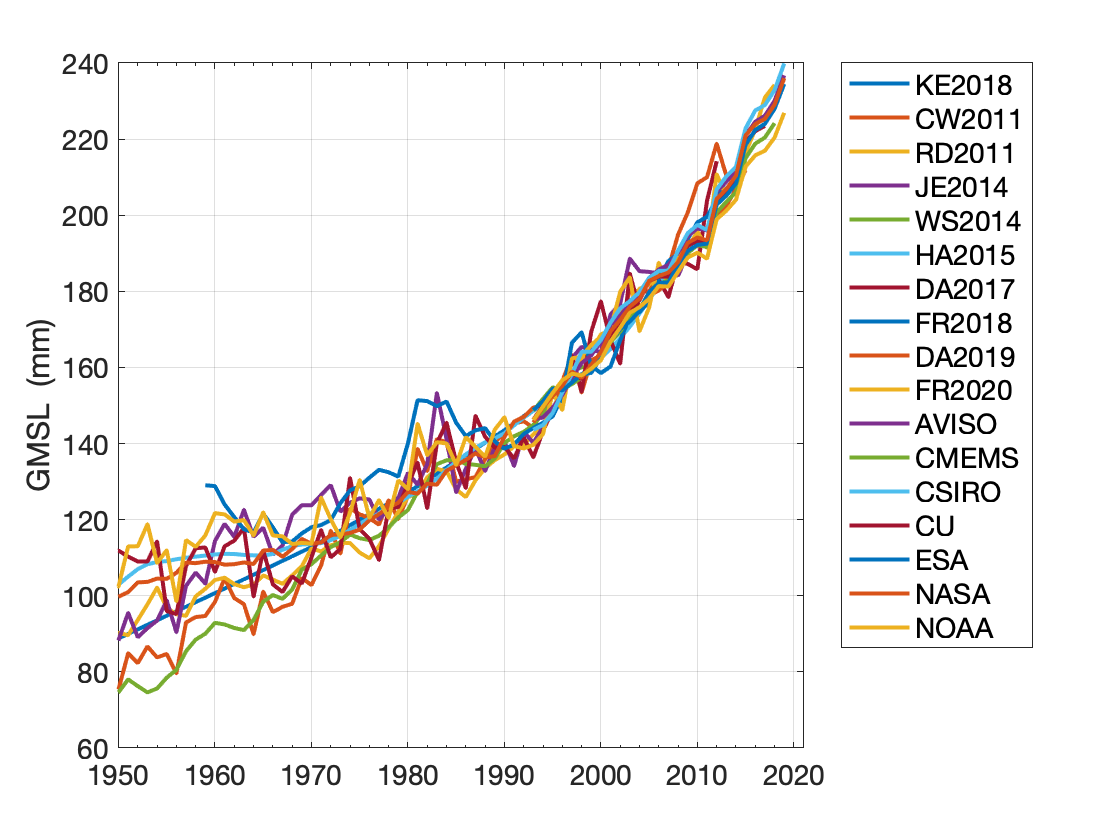



% recons 1950
figure
nn = 1:17;
plot(gmsl_yr_time,gmsl_yr_obs(nn,:),'linew',2),hold on
hleg = legend(fname(nn),'location','bestoutside','fontsize',14);
grid on, axis square
ylabel('GMSL  (mm)')
set(gca,'xtick',1950:10:2022,'xminortick','on','fontsize',14,'xlim',[1950 2021])
orient tall
ff = ['print /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/fig_GMSL_02_ALL_1970_2021.png -dpng'];
eval(ff)

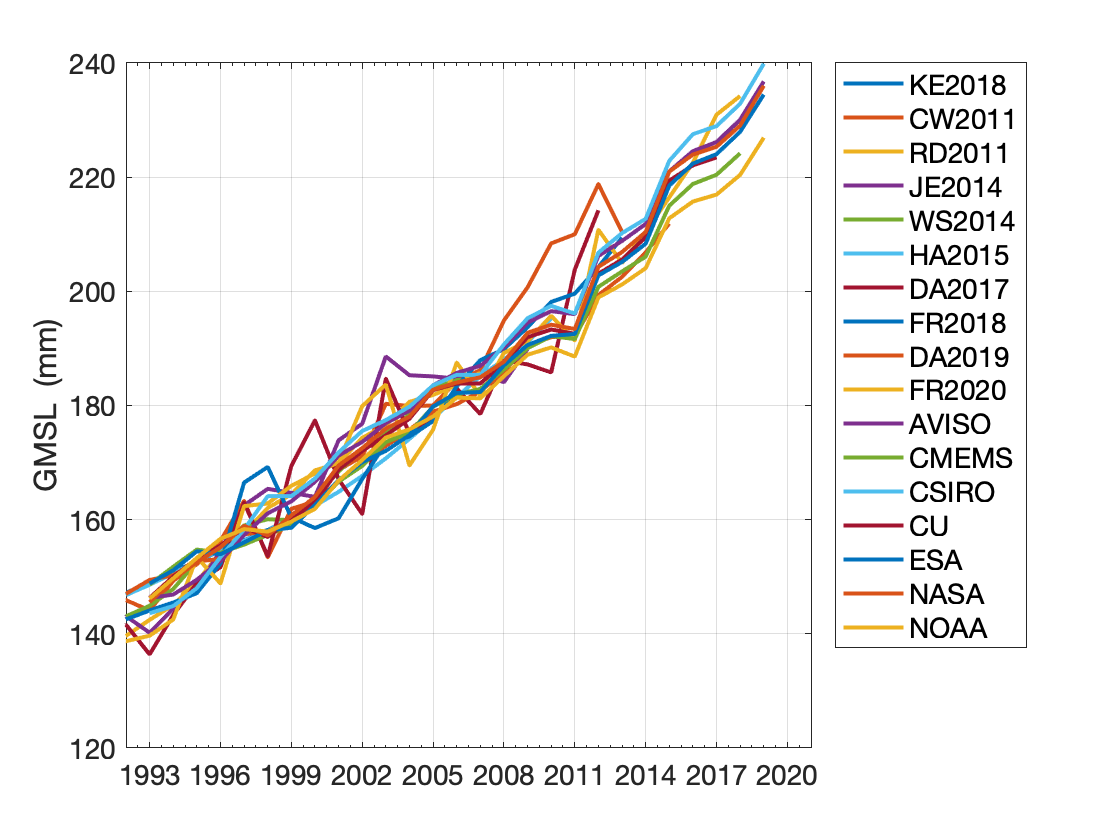



% altim all
figure
nn = 1:17;
plot(gmsl_yr_time,gmsl_yr_obs(nn,:),'linew',2),hold on
hleg = legend(fname(nn),'location','bestoutside','fontsize',14);
grid on, axis square
ylabel('GMSL  (mm)')
set(gca,'xtick',1993:3:2022,'xminortick','on','fontsize',14,'xlim',[1992 2021])

ff = ['print /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/fig_GMSL_03_1993_2021.png -dpng'];
eval(ff)

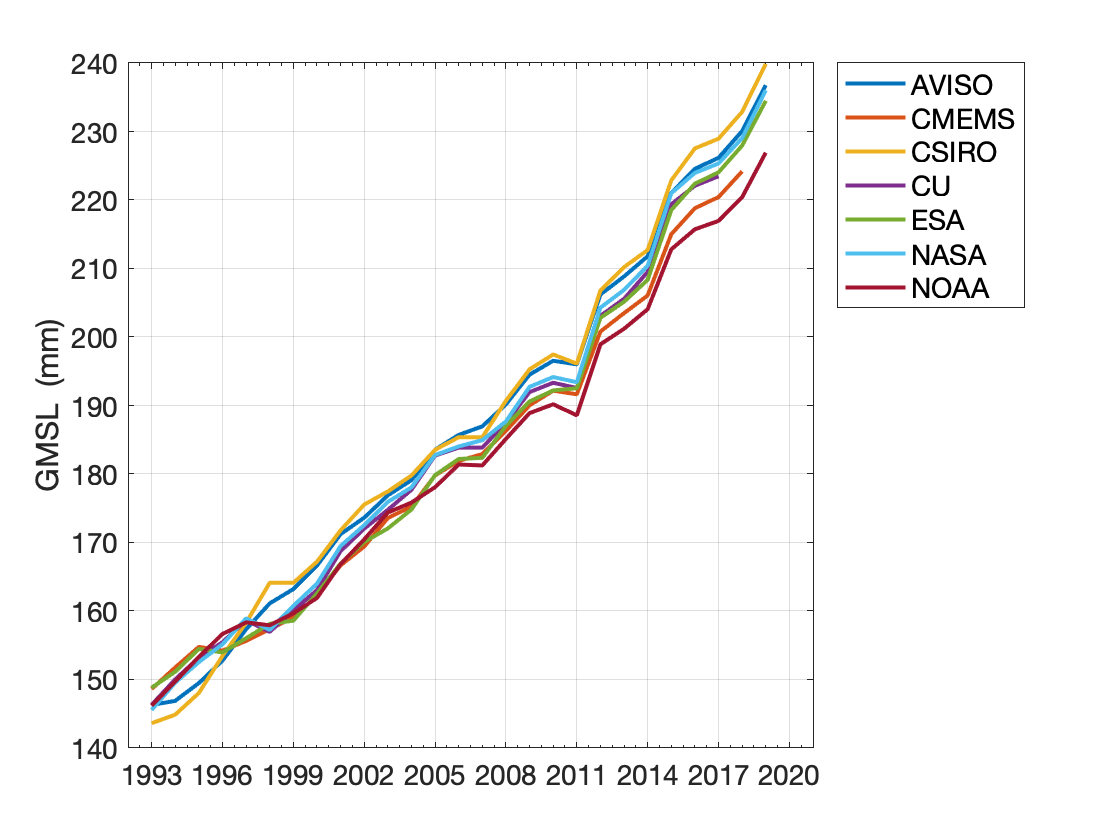



% altim only
figure
nn = 11:17;
plot(gmsl_yr_time,gmsl_yr_obs(nn,:),'linew',2),hold on
hleg = legend(fname(nn),'location','bestoutside','fontsize',14);
grid on, axis square
ylabel('GMSL  (mm)')
set(gca,'xtick',1993:3:2022,'xminortick','on','fontsize',14,'xlim',[1992 2021])

ff = ['print /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/fig_GMSL_04_1993_2021_altim_only.png -dpng'];
eval(ff)

## altim only with offset - later years

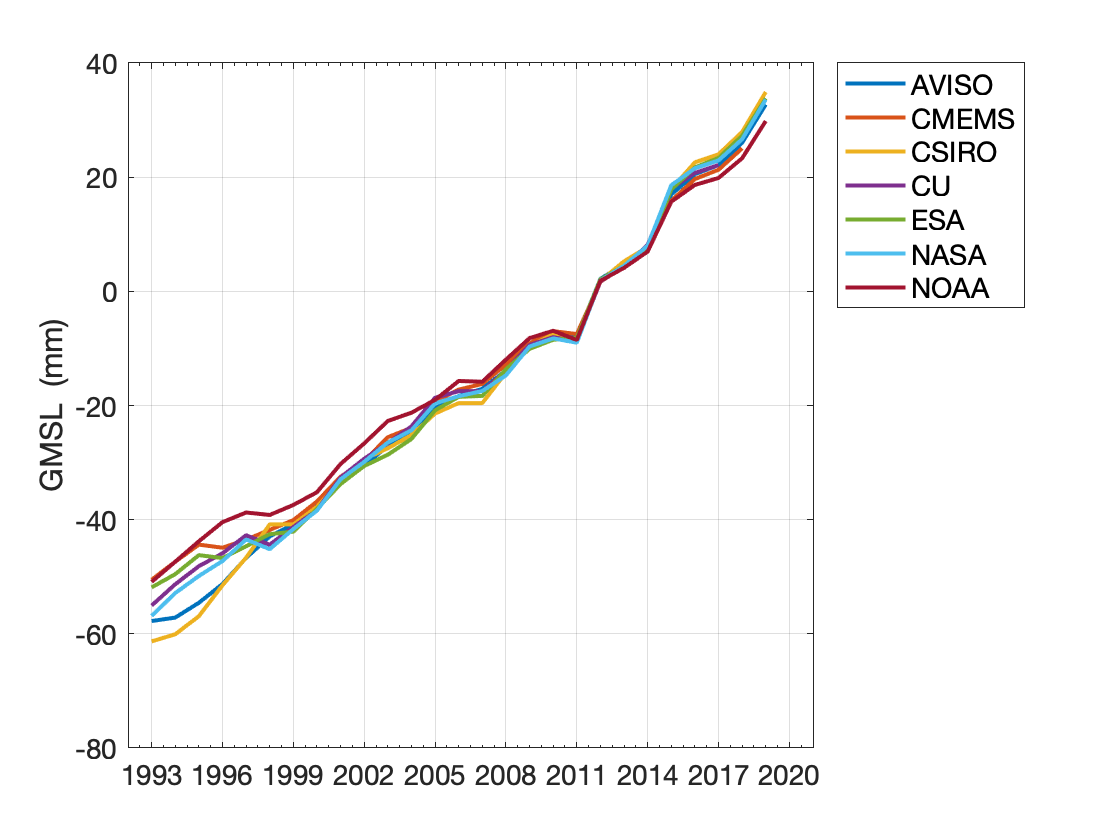

imean_2006_2017 =  gmsl_yr_time >= 2006 & gmsl_yr_time <= 2017;

% baseline 2006-2017
for i = 11:17
    mean_2006_2017  = mean(gmsl_yr_obs(i,imean_2006_2017));
  
    if isnan(mean_1993_2000)~=1
        dummy = gmsl_yr_obs(i,:) - mean_2006_2017;
    gmsl_yr_obs_altim_offset(i,:) = dummy;  
    end
end  

% altim only - offset 2006-2017
figure
nn = 11:17;
plot(gmsl_yr_time,gmsl_yr_obs_altim_offset(nn,:),'linew',2),hold on
hleg = legend(fname(nn),'location','bestoutside','fontsize',14);
grid on, axis square
ylabel('GMSL  (mm)')
set(gca,'xtick',1993:3:2022,'xminortick','on','fontsize',14,'xlim',[1992 2021])

ff = ['print /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/fig_GMSL_04_1993_2021_altim_only_offset.png -dpng'];
eval(ff)

## print figures

## save file & script with timestamp

gmsl_script_path = mfilename('fullpath');

gmsl_script_copy      = evalc(['type ',gmsl_script_path,'.m']);

gmsl_units = 'mm';


ff = ['save /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/IPCC_AR6_CH2_GMSL_',datestr(now,'yyyy-mm-dd'),' gmsl*  ffull -v7'];
eval(ff)


close all, clc

# Paleo data - Darrell 

# Import data from spreadsheet

  data:  http://www.ncdc.noaa.gov/paleo/study/19982     

  citation:  Spratt and Lisiecki, 2016 (10.5194/cp-12-1-2016)     

  prefered reconstruction:  Figure 2c - composite of the short (0–431 ka) and long (431–798 ka) time windows 

  adjusted:  added 8.49 m to adjust 0 ka to 0 m GMSL       

  errors:  95% confidence levels      

Reconstructions of GMSL from marine oxygen isotopes in foraminifera shells show variations of more than 100 m over intervals of 10k -100k years during glacial-interglacial cycles of the Quaternary (McManus et al., 1999; Miller et al., 2020; Shackleton, 1987; Waelbroeck et al., 2002). Correction for past temperatures and a calibration for ice-volume changes implies uncertainty estimates of ± 10-13 m (± 1 SD) (Grant et al., 2014; Shakun et al., 2015; Spratt & Lisiecki, 2016). A recent marine oxygen-isotope-based GMSL reconstruction (Spratt and Lisiecki, 2016) agrees with previous reconstructions, while focusing on the past 800 kyr (Figure 2.28). It shows that GMSL during the Holocene was among the highest over this entire interval, and was surpassed only during the LIG (Marine Isotope Stage 5e) and Marine Isotope Stage 11 (MIS 11) (*medium confidence*); however, relatively brief (about 2 kyr) highstands during interglacial periods might be obscured by dating limitations.

For the last 3 kyr, GMSL has been estimated from global databases of sea-level proxies, including numerous densely-sampled high-resolution salt-marsh records with decimetre scale vertical resolution and subcentennial temporal resolution (Kemp et al., 2018; Kopp et al., 2016). Over the last about 1.5 kyr, the most prominent GMSL trends include a decline at an average rate of -0.4 ± 0.4 mm yr-1 over 950 to 1100 CE and a sustained increase of GMSL that began between 1820 and 1860 and has continued to the present day (Kemp et al., 2018; Kopp et al., 2016). New analyses demonstrate that it is *very likely* that GMSL rise over the 20th century was faster than over any preceding century in at least 3 kyr (Kemp et al., 2018; Kopp et al., 2016)(Figure 2.28). 

## Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 2021-Feb-23 12:54:56

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 18);

% Specify sheet and range
opts.Sheet = "data";
opts.DataRange = "A3:R801";

% Specify column names and types
opts.VariableNames = ["age_calkaBP", "VarName2", "SeaLev_shortPC1", "SeaLev_shortPC1_err_sig", "SeaLev_shortPC1_err_lo", "SeaLev_shortPC1_err_up", "SeaLev_longPC1", "SeaLev_longPC1_err_sig", "SeaLev_longPC1_err_lo", "SeaLev_longPC1_err_up", "VarName11", "SeaLev_shortlong", "SeaLev_err_lo", "SeaLev_err_up", "VarName15", "SeaLev_shortlong1", "SeaLev_err_lo1", "SeaLev_err_up1"];
opts.VariableTypes = ["double", "string", "double", "double", "double", "double", "double", "double", "double", "double", "string", "double", "double", "double", "string", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["VarName2", "VarName11", "VarName15"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["VarName2", "VarName11", "VarName15"], "EmptyFieldRule", "auto");

% Import the data
kyrGMSLSprattandLisieckiS1 = readtable("/Users/dom032/Dropbox/Collaboration (2018) - IPCC AR6/Data/03_FGD_duplicate/SL/SL_paleo_Darrell/800 kyr GMSL (Spratt and Lisiecki).xlsx", opts, "UseExcel", false)

kyrGMSLSprattandLisieckiS1 = 799×18 table
    age_calkaBP    VarName2    SeaLev_shortPC1    SeaLev_shortPC1_err_sig    SeaLev_shortPC1_err_lo    SeaLev_shortPC1_err_up    SeaLev_longPC1    SeaLev_longPC1_err_sig    SeaLev_longPC1_err_lo    SeaLev_longPC1_err_up    VarName11    SeaLev_shortlong    SeaLev_err_lo    SeaLev_err_up    VarName15    SeaLev_shortlong1    SeaLev_err_lo1    SeaLev_err_up1
    ___________    ________    _______________    _______________________    ______________________    ______________________    ______________    _____________________

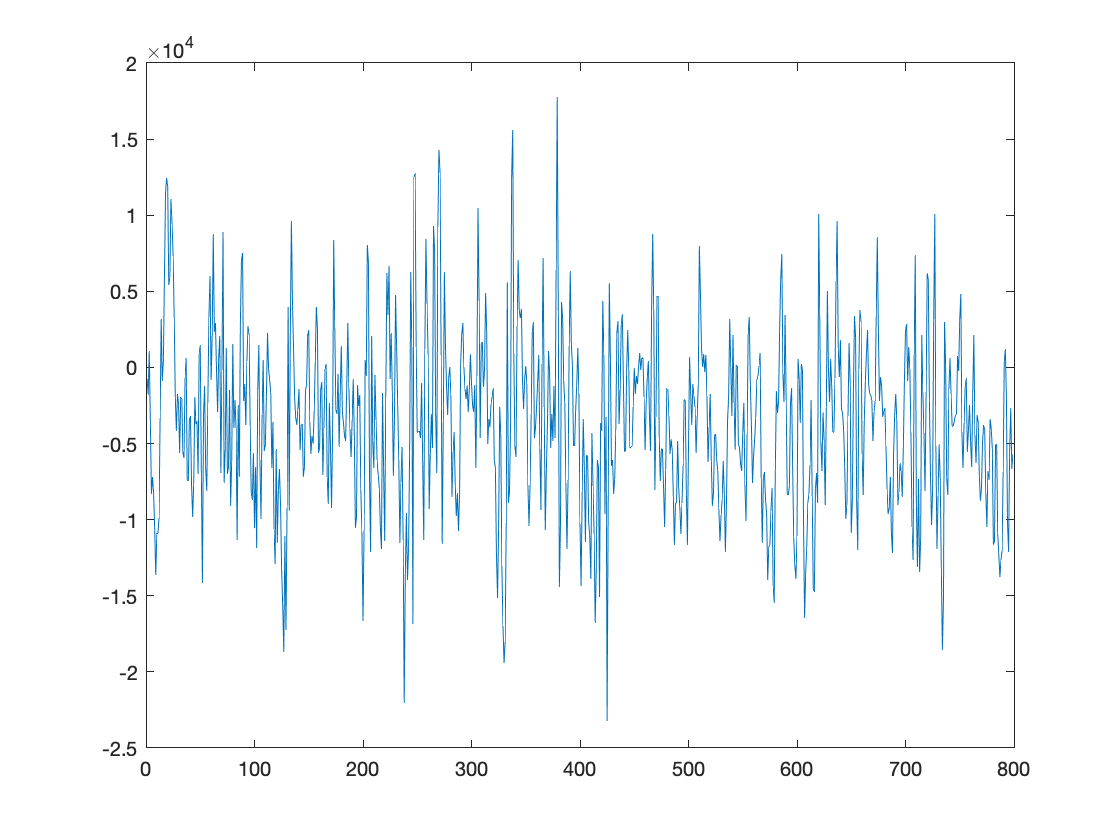

clear opts

% columns A, P, Q, R - transform m into mm 
pal_time    = table2array(kyrGMSLSprattandLisieckiS1(:,1));
pal_sl      = table2array(kyrGMSLSprattandLisieckiS1(:,16))*1e3;
pal_sl_emin = table2array(kyrGMSLSprattandLisieckiS1(:,17))*1e3;
pal_sl_emax = table2array(kyrGMSLSprattandLisieckiS1(:,18))*1e3;

% error is not symmetric around SL values?
emin = pal_sl - pal_sl_emin;
emax = pal_sl_emax - pal_sl;
plot(emax-emin)

## Plot paleo 

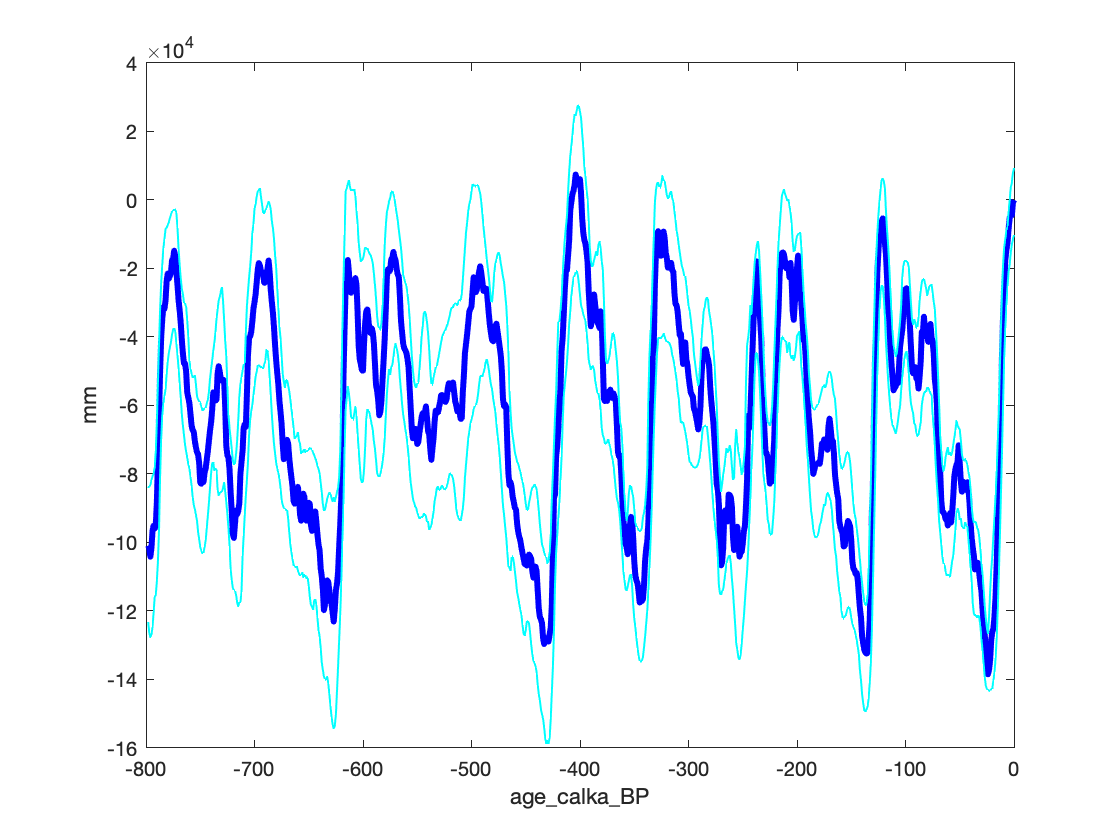

clf
plot(-pal_time,pal_sl,'b','linew',3)
hold on
plot(-pal_time,pal_sl_emin,'c','linew',1)
plot(-pal_time,pal_sl_emax,'c','linew',1)
xlabel('age_calka_BP','interpreter','none'),ylabel('mm') 

ff = ['save /Users/dom032/Dropbox/X_my_scripts/2019_09_ipcc_ar6/SL/IPCC_AR6_CH2_GMSL_',datestr(now,'yyyy-mm-dd'),' gmsl*  ffull  pal_* -v7'];
eval(ff)


%% fix instrumental era/-500 from mm to m

gmsl_yr_obs    = gmsl_yr_obs/1000;
gmsl_yr_obs_er = gmsl_yr_obs_er/1000;
